DEN 435 - Homework 3

%%%%%%%%%%%%%%%%%%%%%

To Do:

DONE. 10/17 ---- 8.3.7 - Surface Plot

Problems: 

DONE. 8.4, 

DONE. 8.5, 

DONE. 8.17

%%%%%%%%%%%%%%%%%%%%%

**Problem 8.2 - 8.3 - Tool life experiment**

- Import data

dFF3 = fullfact([2 2 2])

dFF3 =      1     1     1
     2     1     1
     1     2     1
     2     2     1
     1     1     2
     2     1     2
     1     2     2
     2     2     2


treat = {'(1)';'a';'b';'ab';'c';'ac';'bc';'abc'} % Creates a cell array

treat = 8×1 cell array
    {'(1)'}
    {'a'  }
    {'b'  }
    {'ab' }
    {'c'  }
    {'ac' }
    {'bc' }
    {'abc'}


% Create a grouping variable
gtreat = [treat; treat]

gtreat = 16×1 cell array
    {'(1)'}
    {'a'  }
    {'b'  }
    {'ab' }
    {'c'  }
    {'ac' }
    {'bc' }
    {'abc'}
    {'(1)'}
    {'a'  }
    {'b'  }
    {'ab' }
    {'c'  }
    {'ac' }
    {'bc' }
    {'abc'}



% Replace 1s and 2s with -1s and +1s, respectively, to code the design.
% Initialize array to hold coded variables
dFF3c = nan;
% Repetition structure
for i = 1:length(dFF3(:,1)) % From one to number of number of rows in column 1
    for j = 1:length(dFF3(1,:))
        if dFF3(i,j) == 1
            dFF3c(i,j) = -1;
        else
            dFF3c(i,j) = 1;
        end
    end
end

% Factors
f1 = dFF3c(:,1); % Cutting speed
f2 = dFF3c(:,2); % Metal hardness
f3 = dFF3c(:,3); % Cutting angle
% Table to hold factor levels
tbl80 = table(f1,f2,f3,'VariableNames',{'Factor1','Factor2','Factor3'})

tbl80 = 8×3 table
    Factor1    Factor2    Factor3
    _______    _______    _______

      -1         -1         -1   
       1         -1         -1   
      -1          1         -1   
       1          1         -1   
      -1         -1          1   
       1         -1          1   
      -1          1          1   
       1          1          1   


2. Response column(s)

tlife1 = [221;325;354;552;440;406;605;392]

tlife1 =    221
   325
   354
   552
   440
   406
   605
   392


tlife2 = [311;435;348;472;453;377;500;419]

tlife2 =    311
   435
   348
   472
   453
   377
   500
   419


% Table to hold replicates
tbl831 = table(tlife1,tlife2,'VariableNames',{'Replicate1','Replicate2'})

tbl831 = 8×2 table
    Replicate1    Replicate2
    __________    __________

       221           311    
       325           435    
       354           348    
       552           472    
       440           453    
       406           377    
       605           500    
       392           419    


% Replicates vector
rtlife = [tlife1;tlife2]

rtlife =    221
   325
   354
   552
   440
   406
   605
   392
   311
   435


3. Examine data graphically

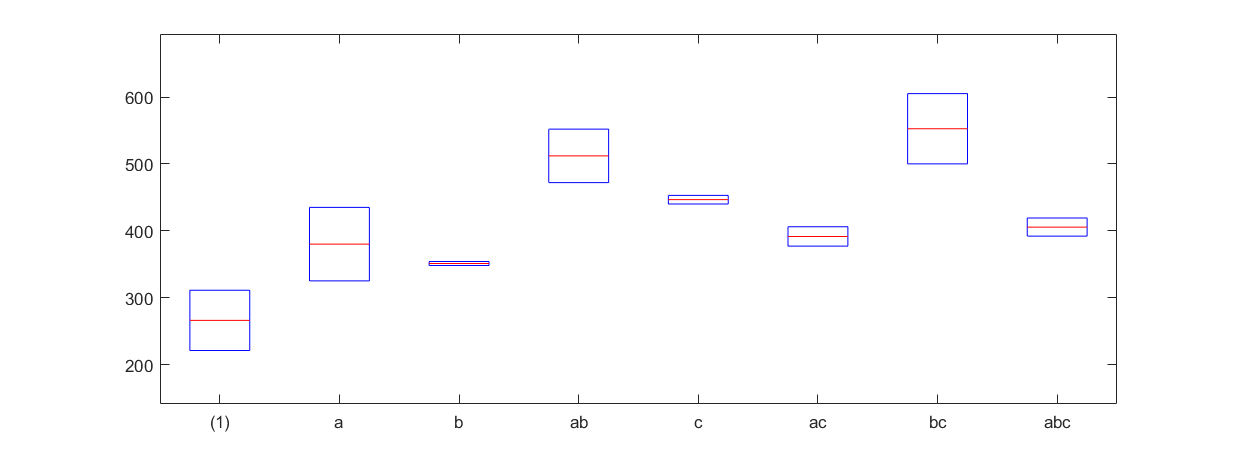

boxplot(rtlife,gtreat)

4. Create Fitted Model

The regression model

Stack (concatenate) the replicates into a single variable.

stlife = stack(tbl831,1:2) % Output is a concatenated table of the replicates.

stlife = 16×2 table
    Replicate1_Replicate2_Indicator    Replicate1_Replicate2
    _______________________________    _____________________

              Replicate1                        221         
              Replicate2                        311         
              Replicate1                        325         
              Replicate2                        435         
              Replicate1                        354         
              Replicate2                        348         
              Replicate1                        552         
              Replicate2                        472         
              Replicate1                        440         
              Replicate2                        453         
              Replicate1                        406         
              Replicate2                        377         
              Replicate1                        605      

Create a table to hold the DOE test matrix and response variables.

tbl832 = table([f1;f1],[f2;f2],[f3;f3],[tlife1;tlife2],'VariableNames',{'CuttingSpeed','MetalHardness','CuttingAngle','ToolLife'})

tbl832 = 16×4 table
    CuttingSpeed    MetalHardness    CuttingAngle    ToolLife
    ____________    _____________    ____________    ________

         -1              -1               -1           221   
          1              -1               -1           325   
         -1               1               -1           354   
          1               1               -1           552   
         -1              -1                1           440   
          1              -1                1           406   
         -1               1                1           605   
          1               1                1           392   
         -1              -1               -1           311   
          1              -1               -1           435   
         -1               1               -1           348   
          1               1          

Linear regression model

Recall: Regression models describe the relationship between a response (output) variable, and one or more predictor (input variables).

mdl = fitlm(tbl832,'ToolLife ~ CuttingSpeed + MetalHardness + CuttingAngle + CuttingSpeed*MetalHardness + CuttingSpeed*CuttingAngle + MetalHardness*CuttingAngle + CuttingSpeed*MetalHardness*CuttingAngle')

mdl = Linear regression model:
    ToolLife ~ 1 + CuttingSpeed*MetalHardness + CuttingSpeed*CuttingAngle + MetalHardness*CuttingAngle + CuttingSpeed:MetalHardness:CuttingAngle

Estimated Coefficients:
                                               Estimate      SE       tStat        pValue  
                                               ________    ______    ________    __________

    (Intercept)                                 413.13     12.406      33.301    7.2169e-10
    CuttingSpeed                                 9.125     12.406     0.73554       0.48302
    MetalHardness                               42.125     12.406      3.3956     0.0094221
    CuttingAngle                                35.875     12.406      2.8918      0.020144
    CuttingSpeed:MetalHardness    

% Remove factors that are not statistically significant.
% mdl2 = removeTerms(mdl,'Factor1')
% mdl3 = removeTerms(mdl2,'Factor1*Factor2')
% mdl4 = removeTerms(mdl3,'Factor2*Factor3')
% mdl5 = removeTerms(mdl4,'Factor1*Factor2*Factor3')

To obtain a more robust model; we then iterate the regression analysis procedure on only the significant terms.

% Or create a new model with only statistically significant terms
mdl2 = fitlm(tbl832,'ToolLife ~ MetalHardness + CuttingAngle + CuttingSpeed:CuttingAngle')

mdl2 = Linear regression model:
    ToolLife ~ 1 + MetalHardness + CuttingAngle + CuttingSpeed:CuttingAngle

Estimated Coefficients:
                                 Estimate      SE       tStat       pValue  
                                 ________    ______    _______    __________

    (Intercept)                   413.13     12.231     33.778    2.8807e-13
    MetalHardness                 42.125     12.231     3.4442     0.0048565
    CuttingAngle                  35.875     12.231     2.9332      0.012529
    CuttingSpeed:CuttingAngle    -59.625     12.231    -4.8751     0.0003817


Number of observations: 16, Error degrees of freedom: 12
Root Mean Squared Error: 48.9
R-squared: 0.787,  Adjusted R-Squared: 0.733
F-statistic vs. constant model: 14.7, p-value = 0.00025

Summary of Fit

R-Square

- Estimates the proportion of variation in the response that can be attributed to the model rather than to random error. Calculated:

- SSmodel / SStotal

R-Square Adj

- Adjusts the R-Square statistic for the number of parameters in the model. R-Square Adj facilitates comparisons among models with different numbers of parameters. Calculated:

- 1 - MSerror / (SStotal / DFtotal)

Root Mean Square Error

- Estimates the standard deviation of the random error.

ANOVA

Prob > F

- The p-value for the test. The Prob > F value measures the probability of obtaining an F Ratio as large as what is observed, given that all parameters except the intercept are zero. Small values of Prob > F indicate that the observed F Ratio is unlikely. Such values are considered evidence that there is at least one significant effect in the model.[[1]](#_ftn1)

Parameter Estimates

Estimate

- The parameter estimates for each term. These are the estimates of the model coefficients (the Beta’s).

[[1]](#_ftnref1) [https://www.jmp.com/support/help/en/15.0/#page/jmp/analysis-of-variance.shtml#ww137405](https://www.jmp.com/support/help/en/15.0/%23page/jmp/analysis-of-variance.shtml%23ww137405)

5. Plot Residuals

Residuals help in checking model quality; these plots help in discovering errors, outliers, or correlations in the model or data.

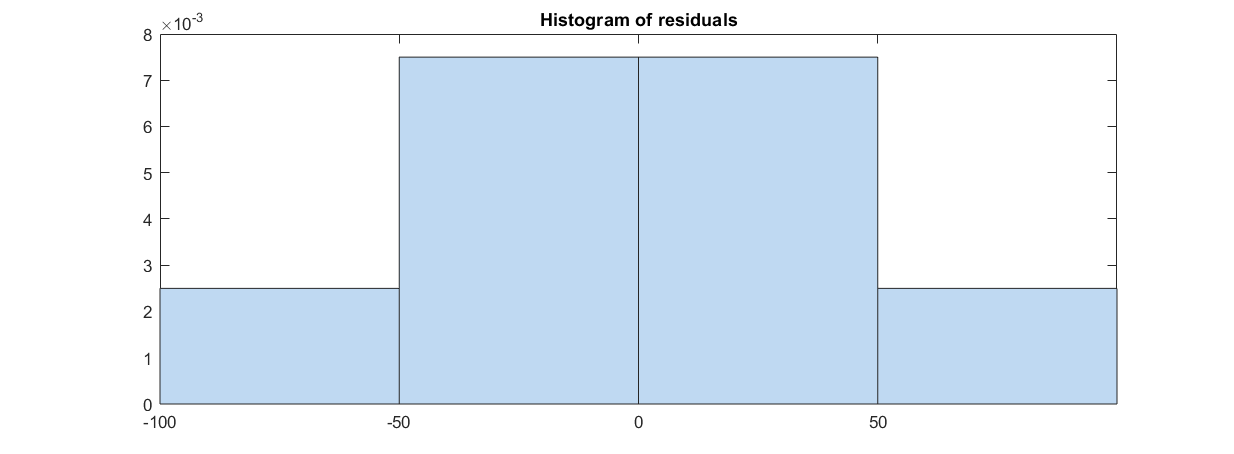

plotResiduals(mdl) % Original model

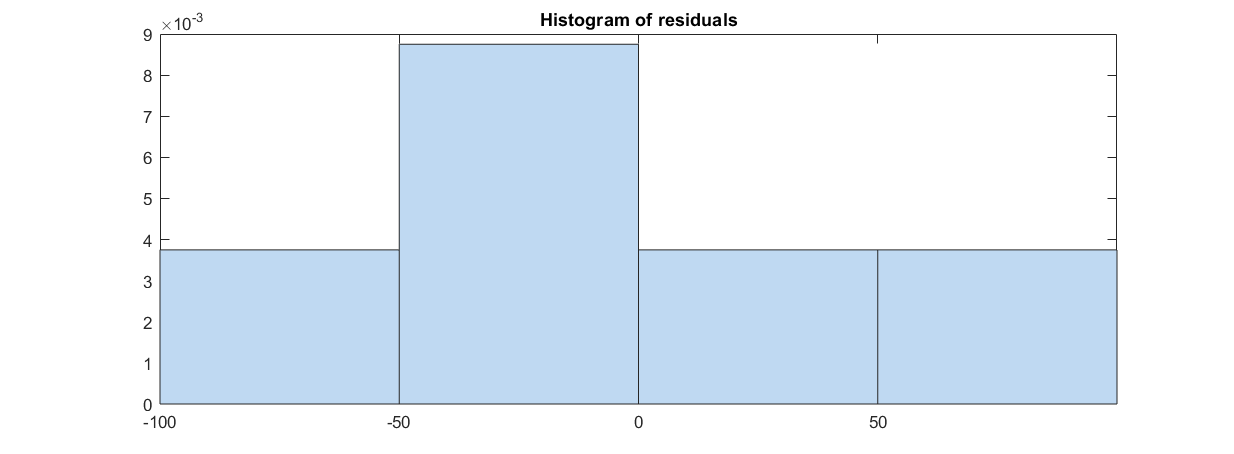

plotResiduals(mdl2) % New model with statistically significant terms only

Residuals histogram plot: shows the range of the residuals and their frequencies. The area of each bar is the relative number of observations. The sum of the bar areas is equal to 1.

The generated histogram plot of the new model does not suggest any problems with model assumptions.

Notice the comparison of the original model and the new model; the original model contains a higher frequency of residuals in the -50 to +50 range as compared to the new model.

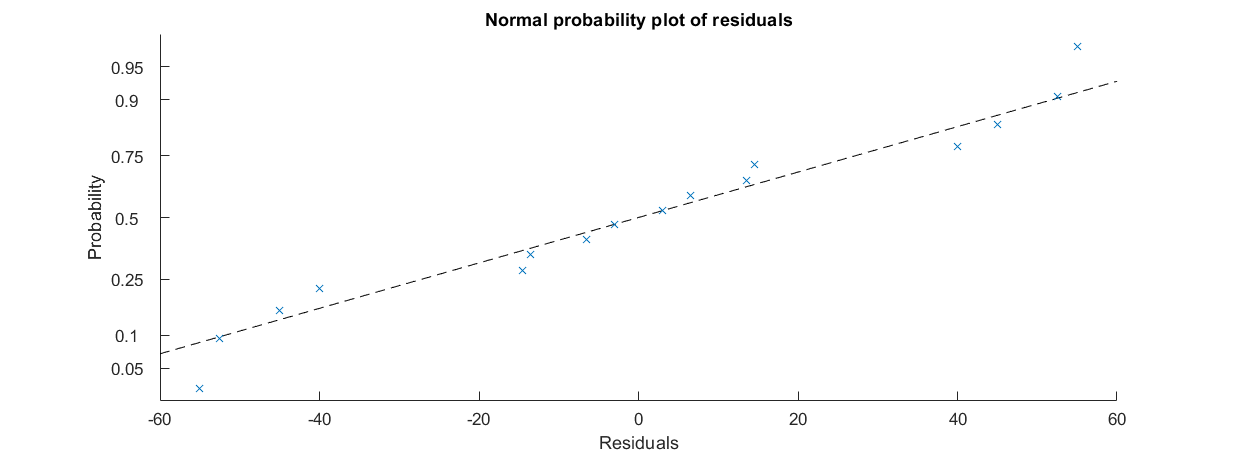

plotResiduals(mdl,'probability') % Original

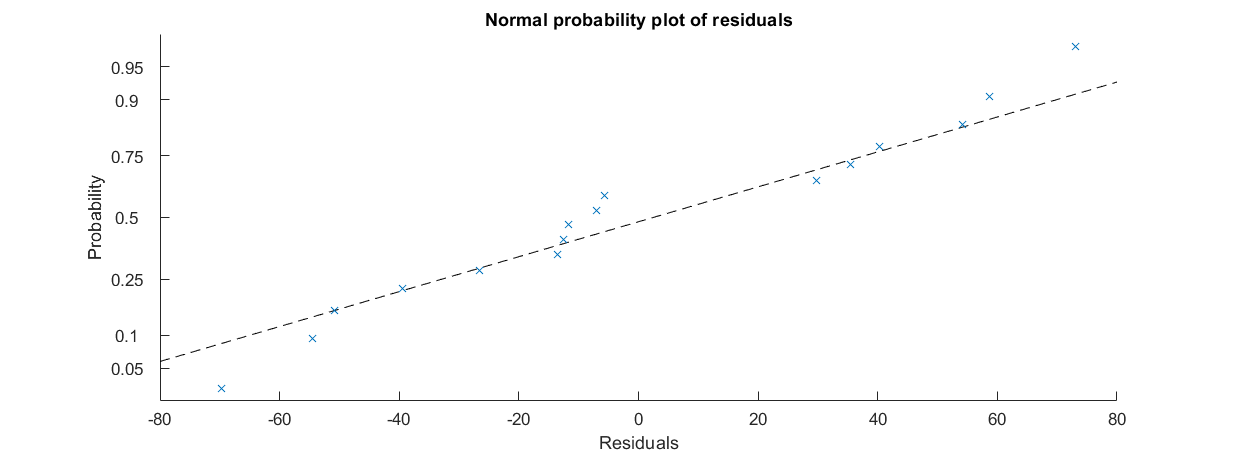

plotResiduals(mdl2,'probability') % New

Normal probability plot of residuals: shows how the distribution of the residuals compares to a normal distribution with matched variance. The probability plot seems reasonably straight, meaning a reasonable fit to normally distributed residuals. 

- Small deviations from the straight line in a normal probability plot are common, but an “S” shaped curve on this graph suggests a bimodal distribution of residuals. *Breaks near the middle of this graph are also indications of abnormalities in the residual distribution.*

Both probability plots are very similar as indicated by the adjusted R-square value for both models.

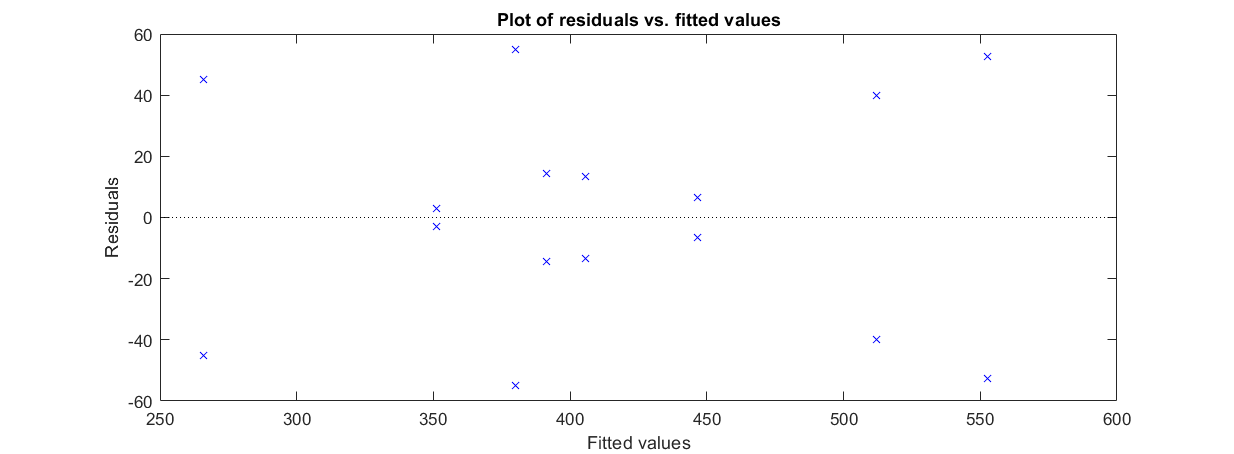

plotResiduals(mdl,'fitted') % Original

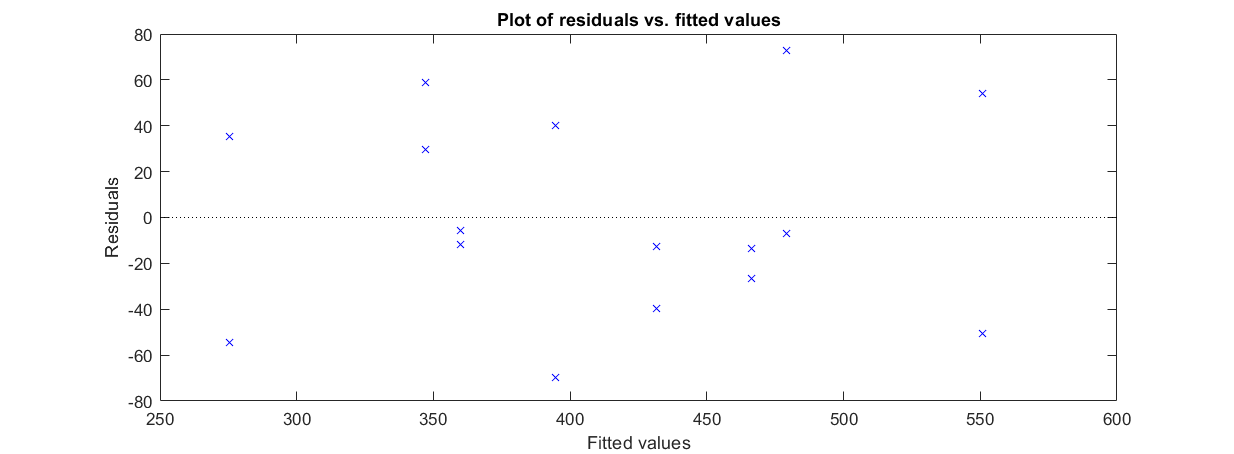

plotResiduals(mdl2,'fitted') % New

Plot of residuals vs. fitted values: the center-line is the fitted model and data points are residuals. The spread among the residuals seems to be consistent across the domain of the model, so we can again conclude that this plot does not suggest any problems with model assumptions.

6. Prediction Profiler

% Plot a prediction profiler
plotSlice(mdl2)

Plot of slices through fitted linear regression surface. Also displays the 95% confidence bounds for the response values.

10/5/21 16:55 @ FH

**8.2 Part. B**

Based off the prediction profiler, the factor-level settings that will produce the longest tool life are:

Cutting speed: -1

Metal hardness: 1 

(note that this doesn't necessarily mean that the level 1 metal is harder than the level -1, as it is not explicitely stated in the problem).

Cutting angle: 1 

**Part. C**

Possibly - it depends on what is indicated by "good results" - however, metal hardness does slope, so it shouldn't be inferred that it is not a factor.

10/11/21 17:43 @ FH

**Fractional Replication** of the above $2^3$ Tool Life Experiment (Problem 8.2 - 8.3)

This is a one half fraction of the $2^k$ design, i.e., Fractional factorial design $2^{k-1}$ runs

See hand notes dated 10/11/21 11:01

The objective of this Fractional Replication model will be to show that the main effects and interaction effects estimates are similiar, but slightly different, for the two designs.

[https://www.mathworks.com/help/stats/fractional-factorial-designs.html](https://www.mathworks.com/help/stats/fractional-factorial-designs.html)

a. Choose basic factors and generators

To find a design that achieves a specified resolution - this is a way to catalog fractional factorial designs according to the alias pattern they produce. 

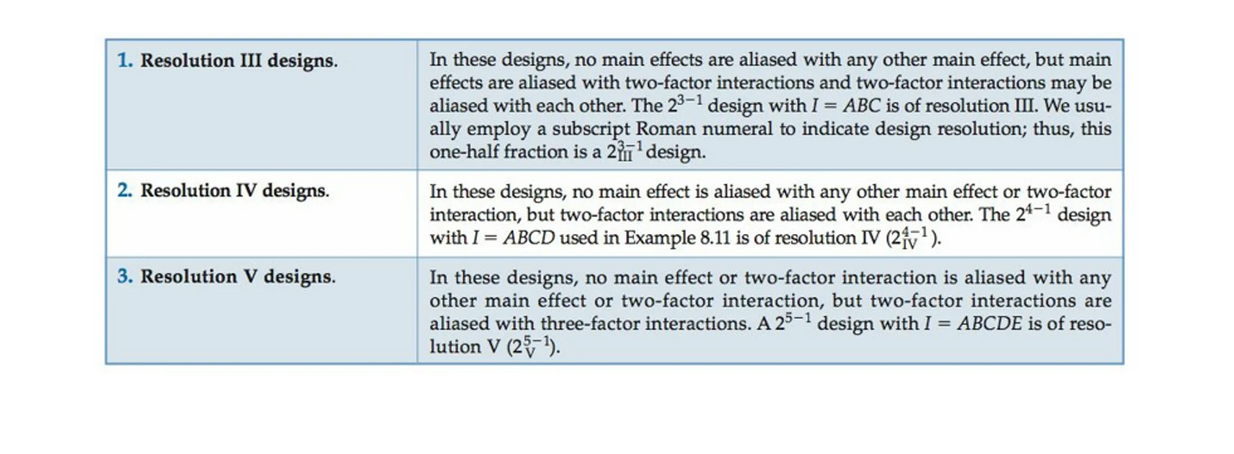

imshow('DesignResolution.png')

in a specified number of runs; use the function `fracfactgen`

generators = fracfactgen('a b c',2,3) % These are generators for 

generators = 3×1 cell array
    {'a' }
    {'b' }
    {'ab'}


% a three-factor design with factors a, b, and c, using 2^2 = 4 runs
% to achieve resolution III.

b. Fractional factorial design

This design `dfF `is constructed by writing down a $2^2$ in the factors A (CuttingSpeed) and B (MetalHardness) and then setting C (CuttingAngle) = AB.

[dfF,confounding] = fracfact(generators) % This is a two factor design in which two 

dfF =     -1    -1     1
    -1     1    -1
     1    -1    -1
     1     1     1


confounding = 7×3 cell array
    {'Term' }    {'Generator'}    {'Confounding'}
    {'X1'   }    {'a'        }    {'X1 + X2*X3' }
    {'X2'   }    {'b'        }    {'X2 + X1*X3' }
    {'X3'   }    {'ab'       }    {'X3 + X1*X2' }
    {'X1*X2'}    {'ab'       }    {'X3 + X1*X2' }
    {'X1*X3'}    {'b'        }    {'X2 + X1*X3' }
    {'X2*X3'}    {'a'        }    {'X1 + X2*X3' }


% two-level basic factors are measured in every combination of levels,
% while the remaining factor (c) is measured only at levels defined
% by the generator ab.

The resulting design from `dfF `has the defining relation *I = ABC.*

An optional output from `fracfact` displays the *confounding pattern *of the design, `confounding.`

The 'Confounding' column represents the **sequence** of the fractional factorial design used to estimate the effect - i.e., the 'Term' column. 

c. Create a table to hold the DOE test matrix and the response data that corresponds to the runs in the fraction. The table will be concatenated for the two replicates.

tlife1c = [440;354;325;392]; % Replicate 1, corresponding to runs from dfF
tlife2c = [453;348;435;419]; % Replicate 2
tbl832c = table([dfF(:,1);dfF(:,1)],[dfF(:,2);dfF(:,2)],[dfF(:,3);dfF(:,3)],[tlife1c;tlife2c],'VariableNames',{'CuttingSpeed','MetalHardness','CuttingAngle','ToolLife'})

tbl832c = 8×4 table
    CuttingSpeed    MetalHardness    CuttingAngle    ToolLife
    ____________    _____________    ____________    ________

         -1              -1                1           440   
         -1               1               -1           354   
          1              -1               -1           325   
          1               1                1           392   
         -1              -1                1           453   
         -1               1               -1           348   
          1              -1               -1           435   
          1               1                1           419   


d. Linear regression model

Recall: Regression models describe the relationship between a response (output) variable, and one or more predictor (input variables).

% *** 10/11/21 19:32 -- edit this...
mdlc = fitlm(tbl832c,'ToolLife ~ CuttingSpeed + MetalHardness + CuttingAngle')

mdlc = Linear regression model:
    ToolLife ~ 1 + CuttingSpeed + MetalHardness + CuttingAngle

Estimated Coefficients:
                     Estimate      SE       tStat        pValue  
                     ________    ______    ________    __________

    (Intercept)       395.75     14.271      27.731    1.0058e-05
    CuttingSpeed          -3     14.271    -0.21022       0.84377
    MetalHardness      -17.5     14.271     -1.2263       0.28735
    CuttingAngle       30.25     14.271      2.1197       0.10138


Number of observations: 8, Error degrees of freedom: 4
Root Mean Squared Error: 40.4
R-squared: 0.602,  Adjusted R-Squared: 0.303
F-statistic vs. constant model: 2.01, p-value = 0.254

e. Add interaction terms, noting that a Resolution III design has main effects that are aliased with two-factor interactions and two-factor interactions may be aliased with each other.

mdlc2 = addTerms(mdlc,'CuttingSpeed*MetalHardness')

mdlc2 = Linear regression model:
    ToolLife ~ 1 + CuttingAngle + CuttingSpeed*MetalHardness

Estimated Coefficients:
                                  Estimate      SE       tStat        pValue  
                                  ________    ______    ________    __________

    (Intercept)                    395.75     14.271      27.731    0.00010293
    CuttingSpeed                       -3     14.271    -0.21022       0.84696
    MetalHardness                   -17.5     14.271     -1.2263       0.30757
    CuttingAngle                    30.25     14.271      2.1197       0.12422
    CuttingSpeed:MetalHardness          0          0         NaN           NaN


Number of observations: 8, Error degrees of freedom: 4
Root Mean Squared Error: 40.4
R-squared: 0.602,  

It seems that the warning may be caused by having an inadequate number of observations relative to the number of predictors in the model.

[https://www.mathworks.com/matlabcentral/answers/637610-regression-design-matrix-is-rank-deficient-what-to-do-next](https://www.mathworks.com/matlabcentral/answers/637610-regression-design-matrix-is-rank-deficient-what-to-do-next)

This is essentially a warning of **singularity**.

**Singularity - **[math] is a point at which a given mathematical object is not defined.

[https://en.wikipedia.org/wiki/Singularity_(mathematics)](https://en.wikipedia.org/wiki/Singularity_(mathematics))  

mdlc3 = removeTerms(mdlc,'CuttingSpeed')

mdlc3 = Linear regression model:
    ToolLife ~ 1 + MetalHardness + CuttingAngle

Estimated Coefficients:
                     Estimate      SE       tStat       pValue  
                     ________    ______    _______    __________

    (Intercept)       395.75     12.835     30.835    6.7331e-07
    MetalHardness      -17.5     12.835    -1.3635        0.2309
    CuttingAngle       30.25     12.835     2.3569      0.064999


Number of observations: 8, Error degrees of freedom: 5
Root Mean Squared Error: 36.3
R-squared: 0.597,  Adjusted R-Squared: 0.436
F-statistic vs. constant model: 3.71, p-value = 0.103

mdlc4 = addTerms(mdlc3,'CuttingSpeed*MetalHardness')

mdlc4 = Linear regression model:
    ToolLife ~ 1 + CuttingAngle + CuttingSpeed*MetalHardness

Estimated Coefficients:
                                  Estimate      SE       tStat        pValue  
                                  ________    ______    ________    __________

    (Intercept)                    395.75     14.271      27.731    0.00010293
    CuttingSpeed                       -3     14.271    -0.21022       0.84696
    MetalHardness                   -17.5     14.271     -1.2263       0.30757
    CuttingAngle                    30.25     14.271      2.1197       0.12422
    CuttingSpeed:MetalHardness          0          0         NaN           NaN


Number of observations: 8, Error degrees of freedom: 4
Root Mean Squared Error: 40.4
R-squared: 0.602,  

Of course, I am going to get a singularity issue because I've set CuttingAngle, C = CuttingSpeed*MetalHardness, A*B.

Let's add other terms, that are not going to produce a singularity event. 

mdlc5 = addTerms(mdlc,'MetalHardness:CuttingAngle')

mdlc5 = Linear regression model:
    ToolLife ~ 1 + CuttingSpeed + MetalHardness*CuttingAngle

Estimated Coefficients:
                                  Estimate      SE       tStat        pValue  
                                  ________    ______    ________    __________

    (Intercept)                    395.75     14.271      27.731    0.00010293
    CuttingSpeed                       -3     14.271    -0.21022       0.84696
    MetalHardness                   -17.5     14.271     -1.2263       0.30757
    CuttingAngle                    30.25     14.271      2.1197       0.12422
    MetalHardness:CuttingAngle          0          0         NaN           NaN


Number of observations: 8, Error degrees of freedom: 4
Root Mean Squared Error: 40.4
R-squared: 0.602,  

I'm not going to be able to add any two-way interaction terms, because essentially, I have an inadequate number of predictor variables relative to the number of observations.

**Bottom line**: The resolution III fractional factorial design has an inherent limitation on the analysis that can be performed on it.

7. Response by Adjusted Whole Model (Predicted) Plot

plot(mdl2)

 The plot shows the whole model except the constant (intercept) term.

Each 'x' is an observation, the red line is the linear regression line, and the red-dashed lines on either side is the 95% confidence bounds. The slope of the linear regression line is the slope of a fit to the predictors projected onto their best-fitting direction, i.e. the norm of the coefficient vector.

The model as a whole is significant because a 'horizontal line' (the mean the response) does not fit between the confidence bounds.

8. Surface Plot

% Create grid
% Nodes
res = 0.1; % Resolution
x1 = [min(f1):res:max(f1)]; % Column vector from low level to high level in increments of resolution.
x2 = [min(f2):res:max(f2)];
x3 = [min(f3):res:max(f3)];
nx1 = length(x1); % Returns the number of elements in the vector (nodes)
nx2 = length(x2); 
nx3 = length(x3);

% Mesh
[X2,X3] = meshgrid(x2,x3); % meshgrid function returns 2D grid coordinates

% Extract model parameter estimates, known as the regression coefficients
% beta's
betas = mdl2.Coefficients.Estimate;
mu = betas(1,1);
beta2 = betas(2,1);
beta3 = betas(3,1);
beta13 = betas(4,1);

% Evaluate the regression equation at every coordinate within the grid.
% Initalize variable to hold the evaluated equation.
% Main effects only
Zm = nan(nx2,nx3); % This is the variable to hold the value of the response.
for i = 1:nx2 % First loop; i is the index of the grid's row
    for j = 1:nx3 % Second loop; j is the index of the grid's column
        Zm(i,j) = mu + beta2*X2(i,j) + beta3*X3(i,j);
    end
end


% Surface plot
figure;
surfc(X2,X3,Zm); % surfc creates a surface and contour plot
c1 = colorbar;
c1.Label.String = 'Cutting Tool Life';
title('Response Surface for Model');
xlabel('Metal Hardness');
ylabel('Cutting Angle');
zlabel('Tool Life');

% Contour plot
cl = 40; % Number of contour levels (for increased resolution)
figure;
contour(X2,X3,Zm,cl) % 2D contour plot
title('Contour Plot for Model');
xlabel('Metal Hardness');
ylabel('Cutting Angle');
zlabel('Tool Life');
c2 = colorbar;
c2.Label.String = 'Cutting Tool Life';

% Mesh
[X1,X3] = meshgrid(x1,x3);

% Evaluate the regression equation at every coordinate within the grid.
% Interaction effects
Zi = nan(nx1,nx3); % This is the variable to hold the value of the response.
for i = 1:nx1 % First loop; i is the index of the grid's row
    for j = 1:nx3 % Second loop; j is the index of the grid's column
        Zi(i,j) = mu + beta3*X3(i,j) + beta13*X1(i,j)*X3(i,j);
    end
end

% Surface plot
figure;
surfc(X1,X3,Zi); % surfc creates a surface and contour plot
c3 = colorbar;
c3.Label.String = 'Cutting Tool Life';
title('Response Surface for Model');
xlabel('Cutting Speed');
ylabel('Cutting Angle');
zlabel('Tool Life');

% Contour plot
cl = 40; % Number of contour levels (for increased resolution)
figure;
contour(X1,X3,Zi,cl) % 2D contour plot
title('Contour Plot for Model');
xlabel('Cutting Speed');
ylabel('Cutting Angle');
zlabel('Tool Life');
c4 = colorbar;
c4.Label.String = 'Cutting Tool Life';

**Problem 8.4 - Taste of a soft-drink beverage, a 2^4 full-factorial design**

- Enter Data

dFF4 = fullfact([2 2 2 2])

% Replace 1s and 2s with -1s and +1s, respectively, to code the design.
% Initialize array to hold coded variables
dFF4c = nan;
% Repetition structure
for i = 1:length(dFF4(:,1)) % From one to number of number of rows in column 1
    for j = 1:length(dFF4(1,:))
        if dFF4(i,j) == 1
            dFF4c(i,j) = -1;
        elseif dFF4(i,j) == 2
            dFF4c(i,j) = 1;
        end

dFF4 =      1     1     1     1
     2     1     1     1
     1     2     1     1
     2     2     1     1
     1     1     2     1
     2     1     2     1
     1     2     2     1
     2     2     2     1
     1     1     1     2
     2     1     1     2


    end
end
dFF4c
% Factors
sw = dFF4c(:,1); % Type of sweetner
ra = dFF4c(:,2); % Ratio of syrup to water
cb = dFF4c(:,3); % Carbonation level
tp = dFF4c(:,4); % Temperature

2. Response columns

% Replicates vectors
score1 = [188;172;179;185;175;183;190;175;200;170;189;183;201;181;189;178]

dFF4c =     -1    -1    -1    -1
     1    -1    -1    -1
    -1     1    -1    -1
     1     1    -1    -1
    -1    -1     1    -1
     1    -1     1    -1
    -1     1     1    -1
     1     1     1    -1
    -1    -1    -1     1
     1    -1    -1     1


score2 = [195;180;187;178;180;178;180;168;193;178;181;188;188;173;182;182]

% Combined replicates column vector
score = [score1;score2];
% Average
scoreAvg = mean([score1,score2],2)

3. Examine data graphically

% Treatment combinations
treat = {'(1)';'a';'b';'ab';'c';'ac';'bc';'abc';'d';'ad';'bd';'abd';'cd';'acd';'bcd';'abcd'}; % Creates a cell array

score1 =    188
   172
   179
   185
   175
   183
   190
   175
   200
   170


% Create a grouping variable

score2 =    195
   180
   187
   178
   180
   178
   180
   168
   193
   178


gtreat = [treat; treat];

boxplot(score,gtreat)
ylabel('Score');
xlabel('Treatment');

scoreAvg =   191.5000
  176.0000
  183.0000
  181.5000
  177.5000
  180.5000
  185.0000
  171.5000
  196.5000
  174.0000


title('Comparative Box Plot');

Create main effects plots for the treatment means to visualize the magnitude effect of each factor.

The main effect tells us how much the response will change per unit level change in the factor.

maineffectsplot(scoreAvg,{sw,ra,cb,tp},'varnames',{'Sweetner','Ratio','Carbonation','Temperature'})

From a visual inspection, clearly sweetner has the largest effect on the response as seen by the slope of the line. Temperature also seems to have a moderate effect.

Create interaction plots to viusalize interaction effects.

An interaction occurs when the difference in response between the levels of one factor is not the same at all levels of the other factors. 

interactionplot(scoreAvg,{sw,ra,cb,tp},'varnames',{'Sweetner','Ratio','Carbonation','Temperature'});

Clearly there is an interaction between sweetner and ratio. Other less apparent interactions include: sweetner and temperature, carbonation and temperature.

4. Create Fitted Model

The regression model

Create a table to hold the DOE test matrix and response variables.

tbl841 = table([sw;sw],[ra;ra],[cb;cb],[tp;tp],[score1;score2],'VariableNames',{'Sweetner','Ratio','Carbonation','Temperature','Score'})

Linear regression model

Recall: Regression models describe the relationship between a response (output) variable, and one or more predictor (input variables).

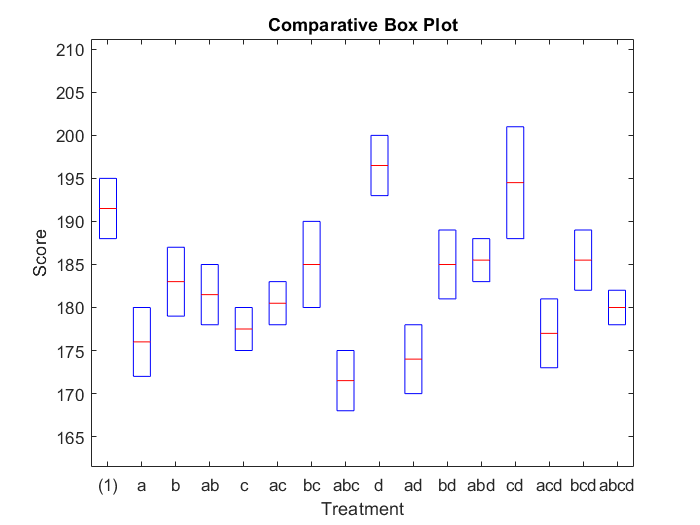

% Perform a linear fit of main effects only
mdl841 = fitlm(tbl841, 'linear','CategoricalVars','Sweetner') % Indicate which factors are categorical.
% Perform a linear fit of main effects and two-way interactions

mdl842 = fitlm(tbl841,'interactions','CategoricalVars','Sweetner')

ANOVA

To examine the quality of the fitted model, consult an ANOVA table.

Recall: ANOVA is used to test H0 (null hypothesis): mu1 = mu2 = mu3 = mu4 = mu5 = mu6 = mu7 = mu8; meaning the mean of each treatment is equal, i.e. there is no difference among the treatments and therefore none of the factors are having an effect on the response.

The null hypothesis is tested against the alternative hypothesis H1: mu1 dne mu2 dne mu3 dne mu4 dne mu5 dne mu6 dne mu7 dne mu8 (dne means 'does not equal'); i.e. some means are different, and therefore some factors ARE having an effect on the response.

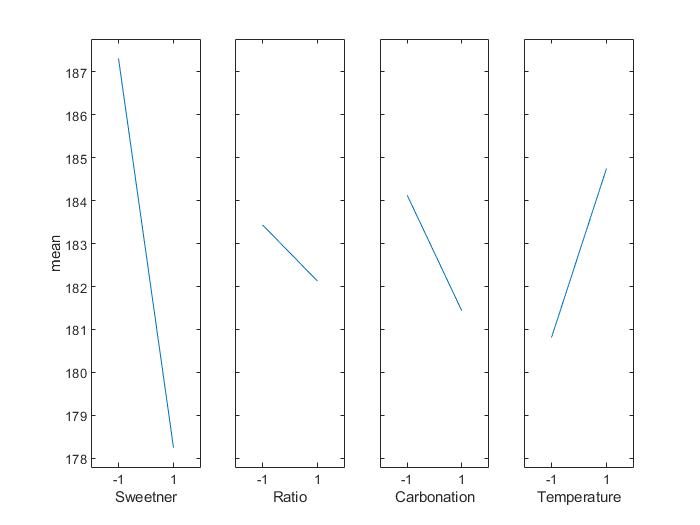

tbl842 = anova(mdl842)

ANOVA gives us two important estimates of variance (sigma-squared):

- The inherent variability within factors is given by MSE (Mean sum of squares due to error within factors).

- The variability between factors is given by MS factor (Mean sum of squares due to factor).

If there are no differences in the factor means (H0), the two estimates MSE and MS factor should be very similar.

*** See handwritten notes dated 10/12/20 - 10/13/20 ***

If MSE and MS factor are not close in value (the difference is large), then we suspect that the observed difference must be caused by differences in the factor means (H1).

Or,                 

If MS factor >> MSE, we can reject the null hypothesis (H0), and therefore inferring the factor is statistically significant (having an effect on the response).

From the ANOVA table we conclude:

Sweetner, Temperature, and Sweetner*Ratio are statistically significant.

Regression on statistically significant terms only.

To obtain a more robust model we iterate the regression analysis procedure on only the statistically significant terms.

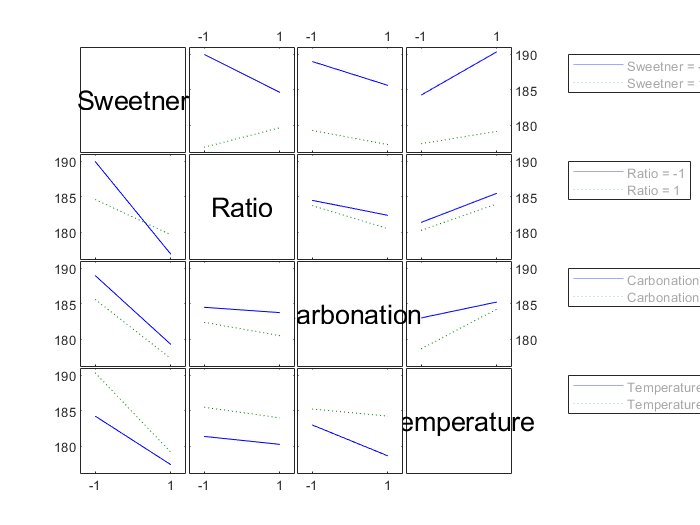

% Or create a new model with only statistically significant terms
mdl843 = fitlm(tbl841,'Score ~ Sweetner + Temperature + Sweetner:Ratio','CategoricalVars','Sweetner')

NOTE: The adjusted R-squared value for mdl843 is higher than the earlier models created, indicating a better fit to the data.

Summary of Fit

R-Square

- Estimates the proportion of variation in the response that can be attributed to the model rather than to random error. Calculated:

- SSmodel / SStotal

R-Square Adj

- Adjusts the R-Square statistic for the number of parameters in the model. R-Square Adj facilitates comparisons among models with different numbers of parameters. Calculated:

- 1 - MSerror / (SStotal / DFtotal)

Root Mean Square Error

- Estimates the standard deviation of the random error.

ANOVA

Prob > F

- The p-value for the test. The Prob > F value measures the probability of obtaining an F Ratio as large as what is observed, given that all parameters except the intercept are zero. Small values of Prob > F indicate that the observed F Ratio is unlikely. Such values are considered evidence that there is at least one significant effect in the model.[[1]](#_ftn1)

Parameter Estimates

Estimate

- The parameter estimates for each term. These are the estimates of the model coefficients (the Beta’s).

[[1]](#_ftnref1) [https://www.jmp.com/support/help/en/15.0/#page/jmp/analysis-of-variance.shtml#ww137405](https://www.jmp.com/support/help/en/15.0/%23page/jmp/analysis-of-variance.shtml%23ww137405)

**Problem 8.5.**

5. Plot Residuals

Residuals help in checking model quality; these plots help in discovering errors, outliers, or correlations in the model or data.

plotResiduals(mdl843)

tbl841 = 32×5 table
    Sweetner    Ratio    Carbonation    Temperature    Score
    ________    _____    ___________    ___________    _____

       -1        -1          -1             -1          188 
        1        -1          -1             -1          172 
       -1         1          -1             -1          179 
        1         1          -1             -1          185 
       -1        -1           1             -1          175 
        1        -1           1             -1          183 
       -1         1           1             -1          190 
        1         1           1             -1          175 
       -1        -1          -1              1          200 
        1        -1          -1              1          170 
       -1         1          -1              1          189 
        1       

plotResiduals(mdl843,'probability')
plotResiduals(mdl843,'fitted')

Residuals histogram plot: shows the range of the residuals and their frequencies. The area of each bar is the relative number of observations. The sum of the bar areas is equal to 1.

The generated histogram plot of the new model does not suggest any problems with model assumptions.

Normal probability plot of residuals: shows how the distribution of the residuals compares to a normal distribution with matched variance. The probability plot seems reasonably straight, meaning a reasonable fit to normally distributed residuals. 

- Small deviations from the straight line in a normal probability plot are common, but an “S” shaped curve on this graph suggests a bimodal distribution of residuals. *Breaks near the middle of this graph are also indications of abnormalities in the residual distribution.*

Plot of residuals vs. fitted values: the center-line is the fitted model and the data points are residuals. The spread among the residuals seems to be consistent across the domain of the model, so we can again conclude that this plot does not suggest any problems with model assumptions.

6. Prediction Profiler

% Plot a prediction profiler
plotSlice(mdl843)

mdl841 = Linear regression model:
    Score ~ 1 + Sweetner + Ratio + Carbonation + Temperature

Estimated Coefficients:
                   Estimate      SE       tStat        pValue  
                   ________    ______    ________    __________

    (Intercept)      187.31    1.6064       116.6    4.9371e-38
    Sweetner_1      -9.0625    2.2719      -3.989    0.00045559
    Ratio          -0.65625    1.1359    -0.57772       0.56824
    Carbonation     -1.3438    1.1359      -1.183       0.24714
    Temperature      1.9688    1.1359      1.7332      0.094474


Number of observations: 32, Error degrees of freedom: 27
Root Mean Squared Error: 6.43
R-squared: 0.433,  Adjusted R-Squared: 0.349
F-statistic vs. constant model: 5.16, p-value = 0.0032

Plot of slices through fitted linear regression surface. Also displays the 95% confidence bounds for the response values.

7. Response by Adjusted Whole Model (Predicted) Plot

plot(mdl843)

mdl842 = Linear regression model:
    Score ~ 1 + Sweetner*Ratio + Sweetner*Carbonation + Sweetner*Temperature + Ratio*Carbonation + Ratio*Temperature + Carbonation*Temperature

Estimated Coefficients:
                               Estimate      SE        tStat        pValue  
                               ________    ______    _________    __________

    (Intercept)                  187.31    1.6504        113.5    9.0593e-31
    Sweetner_1                  -9.0625     2.334      -3.8829     0.0008593
    Ratio                       -2.6875    1.6504      -1.6284       0.11834
    Carbonation                 -1.6875    1.6504      -1.0225       0.31818
    Temperature                  3.0625    1.6504       1.8557      0.077593
    Sweetner_1:Ratio       </

The plot shows the whole model except the constant (intercept) term.

Each 'x' is an observation, the red line is the linear regression line, and the red-dashed lines on either side are the 95% confidence bounds. The slope of the linear regression line is the slope of a fit to the predictors projected onto their best-fitting direction, i.e. the norm of the coefficient vector.

The model as a whole is significant because a 'horizontal line' (the mean the response) does not fit between the confidence bounds.

8. Surface Plot

Main effects only

% Create grid
% Nodes
res = 0.1; % Resolution

tbl842 = 11×5 table
                                SumSq     DF    MeanSq         F         pValue  
                               _______    __    _______    _________    _________

    Sweetner                    657.03     1     657.03       15.077    0.0008593
    Ratio                       13.781     1     13.781      0.31624      0.57983
    Carbonation                 57.781     1     57.781       1.3259      0.26248
    Temperature                 124.03     1     124.03       2.8461      0.10639
    Sweetner:Ratio              132.03     1     132.03       3.0297     0.096387
    Sweetner:Carbonation        3.7813     1     3.7813     0.086768      0.77122
    Sweetner:Temperature        38

xsw = [min(sw):res:max(sw)]; % Column vector from low level to high level in increments of resolution.
xtp = [min(tp):res:max(tp)];
xra = [min(ra):res:max(ra)];

nxsw = length(xsw); % Returns the number of elements in the vector - this becomes
% the nodes on our mesh
nxtp = length(xtp);
nxra = length(xra);

[Xsw,Xtp] = meshgrid(xsw,xtp); % meshgrid function returns 2D grid coordinates

% Extract model parameter estimates, known as the regression coefficients
% beta's
betas = mdl843.Coefficients.Estimate;

mdl843 = Linear regression model:
    Score ~ 1 + Sweetner + Temperature + Sweetner:Ratio

Estimated Coefficients:
                        Estimate      SE       tStat       pValue  
                        ________    ______    _______    __________

    (Intercept)          187.31     1.6065      116.6    3.5898e-39
    Sweetner_1          -9.0625     2.2719     -3.989    0.00043278
    Temperature          1.9687     1.1359     1.7332      0.094071
    Sweetner_1:Ratio      1.375     1.6065    0.85592       0.39931


Number of observations: 32, Error degrees of freedom: 28
Root Mean Squared Error: 6.43
R-squared: 0.412,  Adjusted R-Squared: 0.349
F-statistic vs. constant model: 6.55, p-value = 0.0017

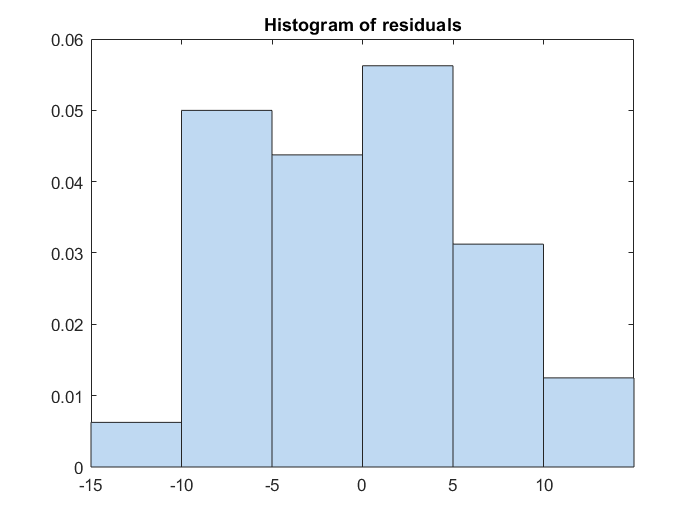

mu = betas(1,1); % Mean
betasw = betas(2,1); % Regression coefficient for sweetner factor, beta
betatp = betas(3,1);
betaswra = betas(4,1);

% Evaluate the regression equation at every coordinate within the grid.
% Initalize variable to hold the evaluated equation.
% Main effects only
Zm = nan; % This is the variable to hold the value of the response.
for i = 1:nxsw % First loop; i is the index of the grid's row
    for j = 1:nxtp % Second loop; j is the index of the grid's column
        Zm(i,j) = mu + betasw*Xsw(i,j) + betatp*Xtp(i,j);
    end
end


% Surface plot
figure;
surfc(Xsw,Xtp,Zm); % surfc creates a surface and contour plot
c1 = colorbar;

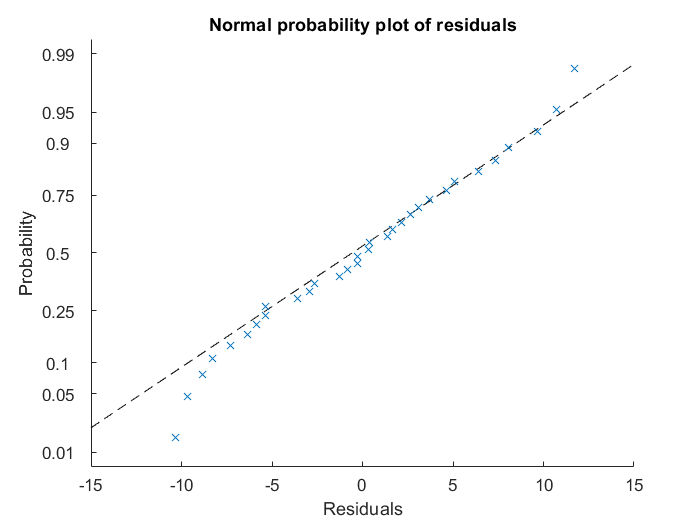

c1.Label.String = 'Score';

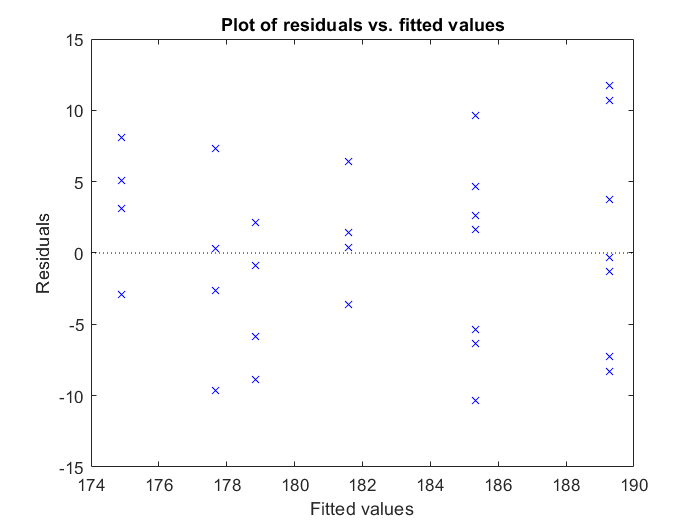

title('Response Surface for Model');

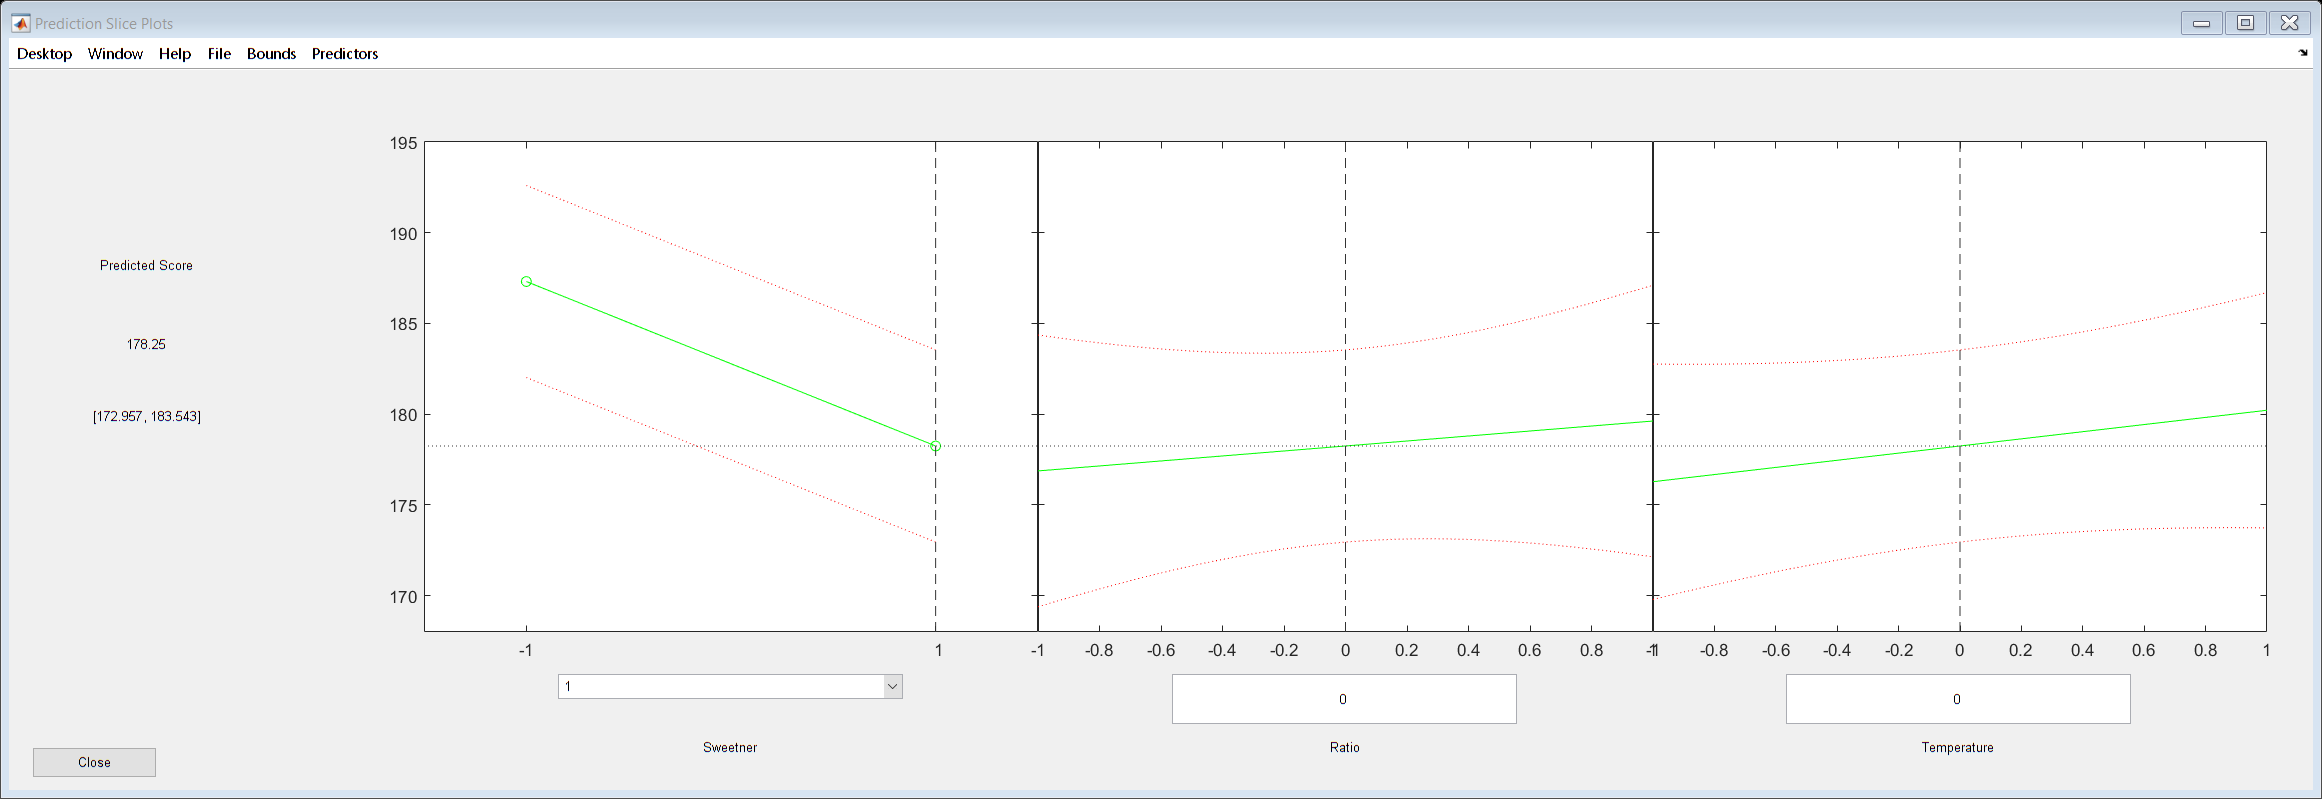

xlabel('Sweetner');
ylabel('Temperature');
zlabel('Score');

% Contour plot
cl = 40; % Number of contour levels (for increased resolution)
figure;
contour(Xsw,Xtp,Zm,cl) % 2D contour plot
title('Contour Plot for Model');

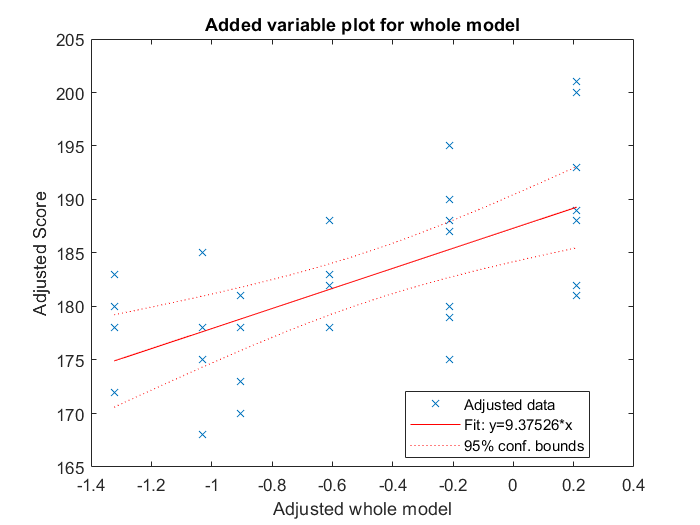

xlabel('Sweetner');
ylabel('Temperature');
zlabel('Score');
c2 = colorbar;

c2.Label.String = 'Score';

The surface plot helps in drawing the conclusion that in order to maximize score, the -1 type of sweetner should be used and the temperature should be set to the high level.

Interaction effects

% Mesh
[Xsw,Xra] = meshgrid(xsw,xra);

% Evaluate the regression equation at every coordinate within the grid.
% Interaction effects
Zi = nan; % This is the variable to hold the value of the response.
for i = 1:nxsw % First loop; i is the index of the grid's row
    for j = 1:nxra % Second loop; j is the index of the grid's column
        Zi(i,j) = mu + betasw*Xsw(i,j) + betaswra*Xsw(i,j)*Xra(i,j);
    end
end

% Surface plot
figure;
surfc(Xsw,Xra,Zi); % surfc creates a surface and contour plot
c3 = colorbar;
c3.Label.String = 'Score';
title('Response Surface for Model');
xlabel('Sweetner');
ylabel('Ratio');
zlabel('Score');

% Contour plot
cl = 40; % Number of contour levels (for increased resolution)
figure;
contour(Xsw,Xra,Zi,cl) % 2D contour plot
title('Response Surface for Model');
xlabel('Sweetner');
ylabel('Ratio');
zlabel('Score');
c4 = colorbar;
c4.Label.String = 'Score';

Additionally, the ratio of syrup to water can be set to anywhere between and including the low and high settings without having an effect on the score, so as long the low sweetner type is used.

**Problem 8.17 - 3^3 Full-factorial design**

- Enter Data

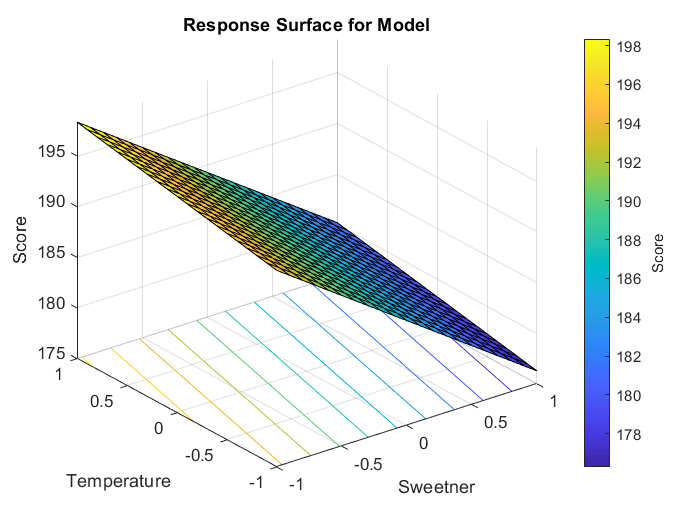

dFF33 = fullfact([3 3 3])

% Replace 1s and 2s with -1s and +1s, respectively, to code the design.
% Initialize array to hold coded variables
dFF33c = nan;
% Repetition structure
for i = 1:length(dFF33(:,1)) % From one to number of number of rows in column 1
    for j = 1:length(dFF33(1,:))

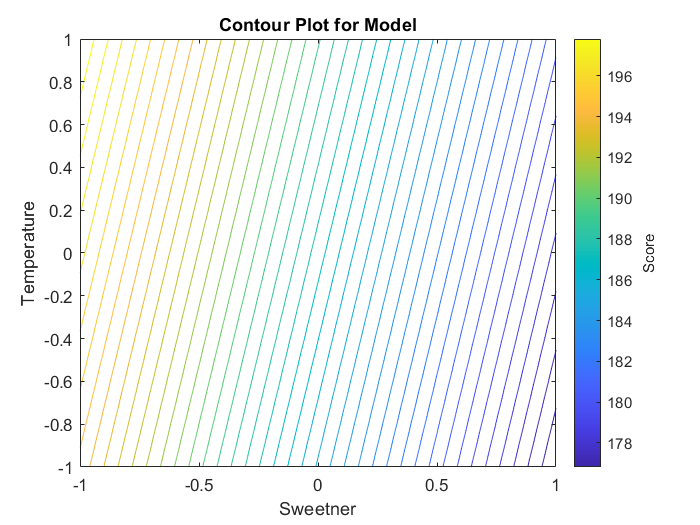

        if dFF33(i,j) == 1
            dFF33c(i,j) = -1;
        elseif dFF33(i,j) == 2
            dFF33c(i,j) = 0;
        elseif dFF33(i,j) == 3
            dFF33c(i,j) = 1;
        end
    end
end
dFF33c
% Factors

fx1 = dFF33c(:,1); % Factor x1
fx2 = dFF33c(:,2); % Factor x2
fx3 = dFF33c(:,3); % Factor x3

2. Response columns

% Response vectors
avgResponse = [24;120.33;213.67;86;136.63;340.67;112.33;256.33;271.67;81;101.67;357;171.33;372;501.67;264;427;730.67;220.67;239.67;422;199;485.33;673.67;176.67;501;1010];
stdDev = [12.49;8.39;42.83;3.46;80.41;16.17;27.57;4.62;23.63;0;17.67;32.91;15.01;0;92.50;63.50;88.61;21.08;133.82;23.46;18.52;29.44;44.67;158.21;55.51;138.94;142.45];

3. Examine data graphically

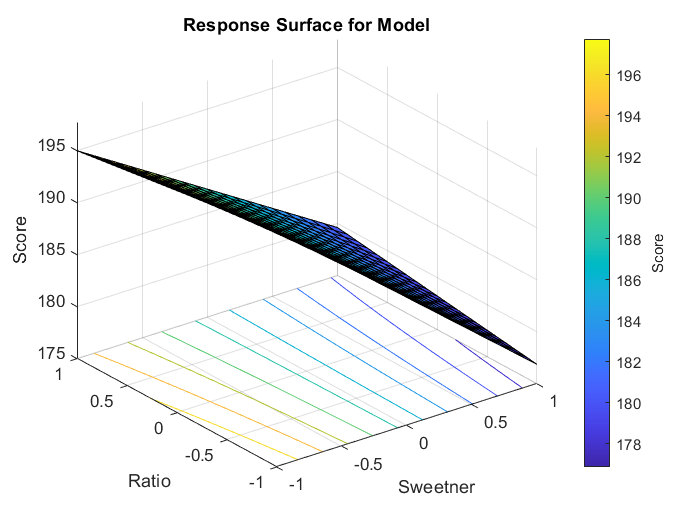

% Create a vector to hold the treatment number
% Initialize
treatment = zeros(length(dFF33c),1);
iterCount = 0;
for k = 1:length(dFF33c(:,1))
    iterCount = iterCount + 1;
    treatment(k,1) = iterCount;
end

% Box plot
boxplot(avgResponse,treatment)
ylabel('AverageResponse');
xlabel('Treatment');
title('Comparative Box Plot');

% Scatter Plots
sp1 = scatter(treatment,avgResponse)
ylabel('Average Response');

xlabel('Treatment');
title('Scatter Plot of Average Response');

sp2 = scatter(treatment,stdDev)
ylabel('Standard Deviation');
xlabel('Treatment');
title('Scatter Plot of Standard Deviation');

Create main effects plots for the treatment means to visualize the magnitude effect of each factor.

The main effect tells us how much the response will change per unit level change in the factor.

maineffectsplot(avgResponse,{fx1,fx2,fx3},'varnames',{'Factorx1','Factorx2','Factorx3'})

From visual inspection, all factors have an effect, with Factor x1 appearing to have the largest effect on the average response.

Create interaction plots to viusalize interaction effects.

An interaction occurs when the difference in response between the levels of one factor is not the same at all levels of the other factors. 

interactionplot(avgResponse,{fx1,fx2,fx3},'varnames',{'Factorx1','Factorx2','Factorx3'});

Interactions appear to minimal across all factors.

4. Create Fitted Model

The regression model

Create a table to hold the DOE test matrix and response variables.

tbl8171 = table(fx1,fx2,fx3,avgResponse,'VariableNames',{'Factorx1','Factorx2','Factorx3','AvgResponse'})

Linear regression model

Recall: Regression models describe the relationship between a response (output) variable, and one or more predictor (input variables).

Part a.

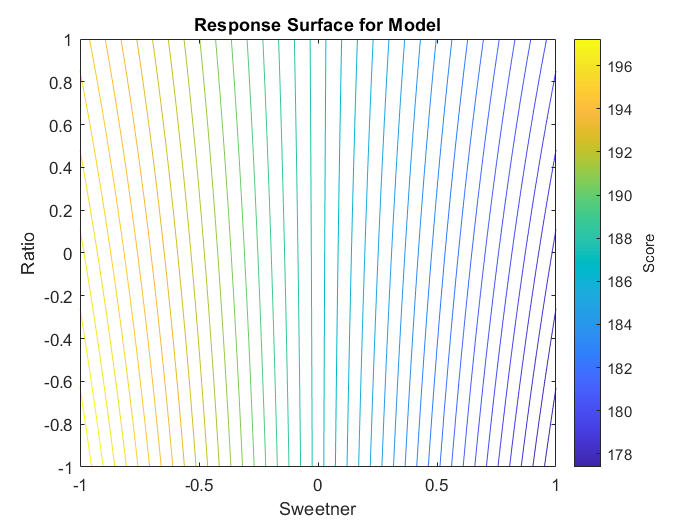

% Perform a quadratic fit to the response

 mdl8171 = fitlm(tbl8171, 'quadratic')

Part b.

tbl8172 = table(fx1,fx2,fx3,stdDev,'VariableNames',{'Factorx1','Factorx2','Factorx3','StdDeviation'})

dFF33 =      1     1     1
     2     1     1
     3     1     1
     1     2     1
     2     2     1
     3     2     1
     1     3     1
     2     3     1
     3     3     1
     1     1     2


mdl8172 = fitlm(tbl8172,'linear')

Part c.

plotSlice(mdl8171)
plotSlice(mdl8172)

Based on the analysis of the plot slice profiles, setting x1 = ~ 0.90, x2 = ~ 0, x3 = -0.07 will produce an avg. response equal to 500 while keeping the std. dev at a minimum.

5. Expand the problem by creating surface plots, contour plots, overlay contour plots to find the optimal region.

First, create a model of only the statistically significant terms for both the avg response model and the standard deviation model.

Consult an ANOVA table:

tbl8173 = anova(mdl8171)

From studying the ANOVA table, we see that MS (for all terms) >> MS_error, with the exception of the second-order terms. Therefore, we reject the Null Hypothesis (there are no differences in treatment means for the corresponding factor) for all terms, and therefore accept that their means differ and have an effect on the response. The exception will be the second-order terms.

Model for avg response **with only statistically significant terms**:

mdl8173 = fitlm(tbl8171,'AvgResponse ~ Factorx1 + Factorx2 + Factorx3 + Factorx1:Factorx2 + Factorx1:Factorx3 + Factorx2:Factorx3')

dFF33c =     -1    -1    -1
     0    -1    -1
     1    -1    -1
    -1     0    -1
     0     0    -1
     1     0    -1
    -1     1    -1
     0     1    -1
     1     1    -1
    -1    -1     0


Note the adjusted R-Squared value for mdl8173 is slightly higher than mdl8171 (quadratic model), even though there is less terms in the model.

Model for std deviation with only statistically significant terms:

tbl8184 = anova(mdl8172)

Consulting the ANOVA table, we see that all factors have a larger MS than MS_error, therefore there is sufficient evidence to reject the Null Hypothesis for all terms, resulting in all terms being statistically significant.


$$Response = 314.7 + 177x_1 + 109.4x_2 + 131.5x_3 + 66x_1x_2 + 75.5x_1x_3 + 43.6x_2x_3 + 21.67$$


6. Surface and contour plots

Average Response

Terms 1 and 2 only

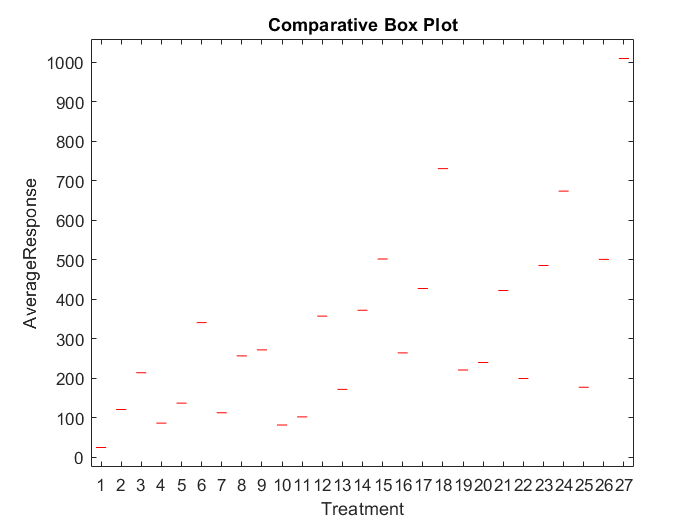

% Create grid
% Nodes
res = 0.1; % Resolution
x1 = [min(fx1):res:max(fx2)]; % Column vector from low level to high level in increments of resolution.
x2 = [min(fx2):res:max(fx2)];
x3 = [min(fx3):res:max(fx3)];

nx1 = length(x1); % Returns the number of elements in the vector - this becomes
% the nodes on our mesh
nx2 = length(x2);
nx3 = length(x3);

[X1,X2] = meshgrid(x1,x2); % meshgrid function returns 2D grid coordinates

% Extract model parameter estimates, known as the regression coefficients
% beta's
betas817 = mdl8173.Coefficients.Estimate;
mu = betas817(1,1); % Mean
beta1 = betas817(2,1); % Regression coefficient for sweetner factor, beta
beta2 = betas817(3,1);
beta3 = betas817(4,1);
beta12 = betas817(5,1);
beta13 = betas817(6,1);

beta23 = betas817(7,1);

% Evaluate the regression equation at every coordinate within the grid.

sp1 =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27]
              YData: [24 120.3300 213.6700 86 136.6300 340.6700 112.3300 256.3300 271.6700 81 101.6700 357 171.3300 372 501.6700 264 427 730.6700 220.6700 239.6700 422 199 485.3300 673.6700 176.6700 501 1010]
              ZData: [1×0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


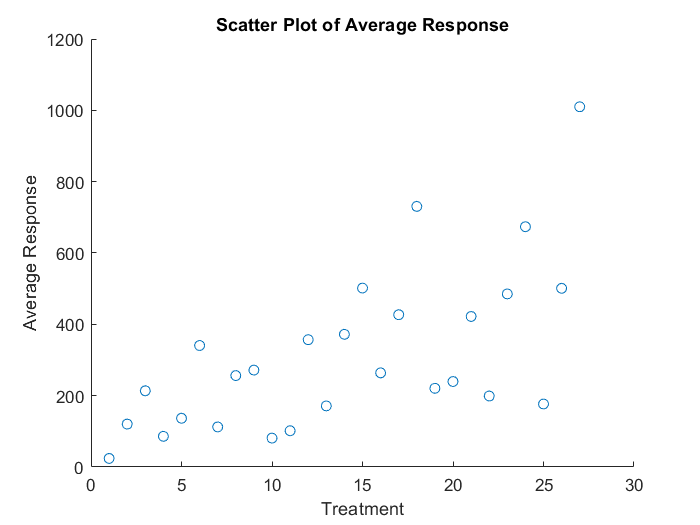

% Initalize variable to hold the evaluated equation.
% Effects from Factor 1 and 2 only
Z12 = nan; % This is the variable to hold the value of the response.

for i = 1:nx1 % First loop; i is the index of the grid's row
    for j = 1:nx2 % Second loop; j is the index of the grid's column

sp2 =   Scatter with properties:

             Marker: 'o'
    MarkerEdgeColor: 'flat'
    MarkerFaceColor: 'none'
           SizeData: 36
          LineWidth: 0.5000
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27]
              YData: [12.4900 8.3900 42.8300 3.4600 80.4100 16.1700 27.5700 4.6200 23.6300 0 17.6700 32.9100 15.0100 0 92.5000 63.5000 88.6100 21.0800 133.8200 23.4600 18.5200 29.4400 44.6700 158.2100 55.5100 138.9400 142.4500]
              ZData: [1×0 double]
              CData: [0 0.4470 0.7410]

  Show all properties


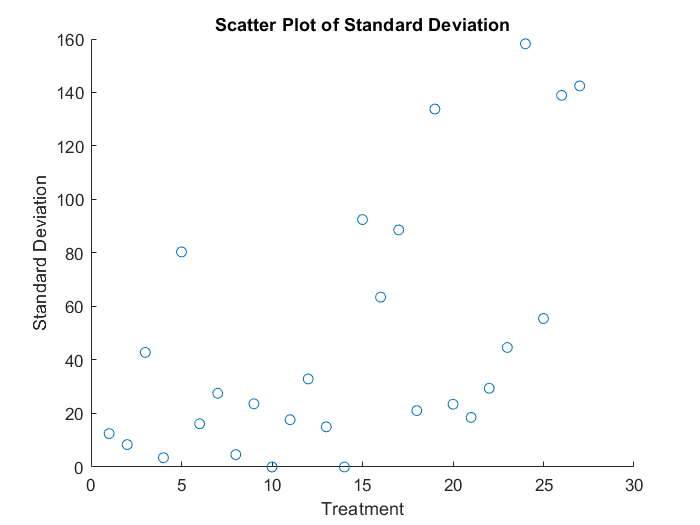

        Z12(i,j) = mu + beta1*X1(i,j) + beta2*X2(i,j) + beta12*X1(i,j)*X2(i,j);
    end
end

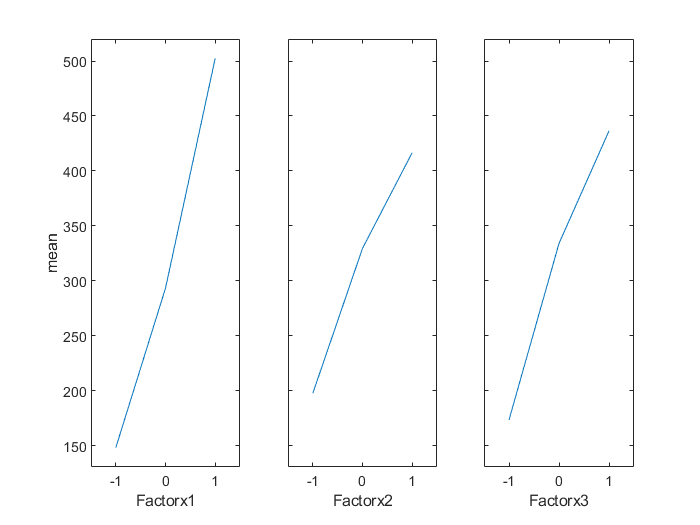


% Surface plot
figure;
surfc(X1,X2,Z12); % surfc creates a surface and contour plot

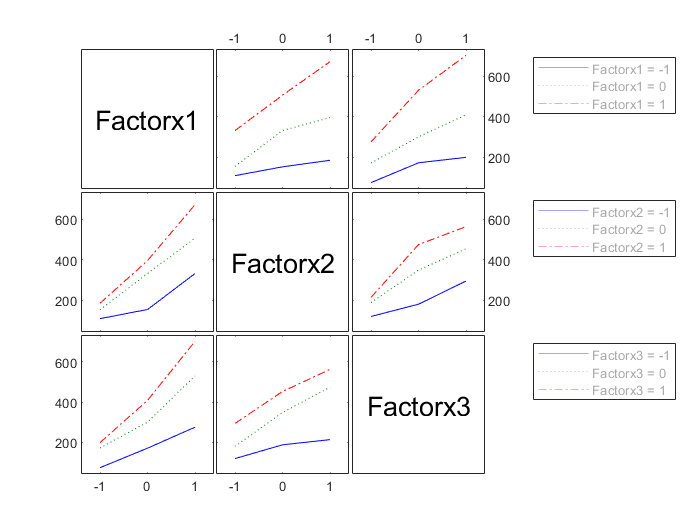

c1 = colorbar;
c1.Label.String = 'Response';
title('Response Surface for Model');
xlabel('x1');
ylabel('x2');

zlabel('Average Response');

% Contour plot
cl = 40; % Number of contour levels (for increased resolution)
figure;
contour(X1,X2,Z12,cl) % 2D contour plot

tbl8171 = 27×4 table
    Factorx1    Factorx2    Factorx3    AvgResponse
    ________    ________    ________    ___________

       -1          -1          -1             24   
        0          -1          -1         120.33   
        1          -1          -1         213.67   
       -1           0          -1             86   
        0           0          -1         136.63   
        1           0          -1         340.67   
       -1           1          -1         112.33   
        0           1          -1         256.33   
        1           1          -1         271.67   
       -1          -1           0             81   
        0          -1           0         101.67   
        1          -1           0            357   
       -1           0           0         171.33   
        0           0           0            372   
        1 

title('Contour Plot for Model');
xlabel('x1');
ylabel('x2');
zlabel('x3');
c2 = colorbar;

mdl8171 = Linear regression model:
    AvgResponse ~ 1 + Factorx1*Factorx2 + Factorx1*Factorx3 + Factorx2*Factorx3 + Factorx1^2 + Factorx2^2 + Factorx3^2

Estimated Coefficients:
                         Estimate      SE       tStat        pValue  
                         ________    ______    ________    __________

    (Intercept)           327.62     38.758      8.4532    1.7101e-07
    Factorx1                 177     17.941      9.8656    1.8872e-08
    Factorx2              109.43     17.941      6.0991    1.1803e-05
    Factorx3              131.47     17.941      7.3276    1.1808e-06
    Factorx1:Factorx2     66.028     21.973      3.0049     0.0079707
    Factorx1:Factorx3     75.471     21.973      3.4346     0.0031616
    Factorx2:F

c2.Label.String = 'Average Response';

Terms 2 and 3 only.

[X2,X3] = meshgrid(x2,x3); % meshgrid function returns 2D grid coordinates

tbl8172 = 27×4 table
    Factorx1    Factorx2    Factorx3    StdDeviation
    ________    ________    ________    ____________

       -1          -1          -1          12.49    
        0          -1          -1           8.39    
        1          -1          -1          42.83    
       -1           0          -1           3.46    
        0           0          -1          80.41    
        1           0          -1          16.17    
       -1           1          -1          27.57    
        0           1          -1           4.62    
        1           1          -1          23.63    
       -1          -1           0              0    
        0          -1           0          17.67    
        1          -1           0          32.91    
       -1           0           0          15.01    
        0           0           0              

% Effects from Factor 2 and 3 only

mdl8172 = Linear regression model:
    StdDeviation ~ 1 + Factorx1 + Factorx2 + Factorx3

Estimated Coefficients:
                   Estimate      SE      tStat       pValue  
                   ________    ______    ______    __________

    (Intercept)     47.995     7.8085    6.1466    2.8587e-06
    Factorx1        11.528     9.5634    1.2054        0.2403
    Factorx2        15.323     9.5634    1.6023       0.12274
    Factorx3        29.192     9.5634    3.0524     0.0056483


Number of observations: 27, Error degrees of freedom: 23
Root Mean Squared Error: 40.6
R-squared: 0.367,  Adjusted R-Squared: 0.284
F-statistic vs. constant model: 4.45, p-value = 0.0132

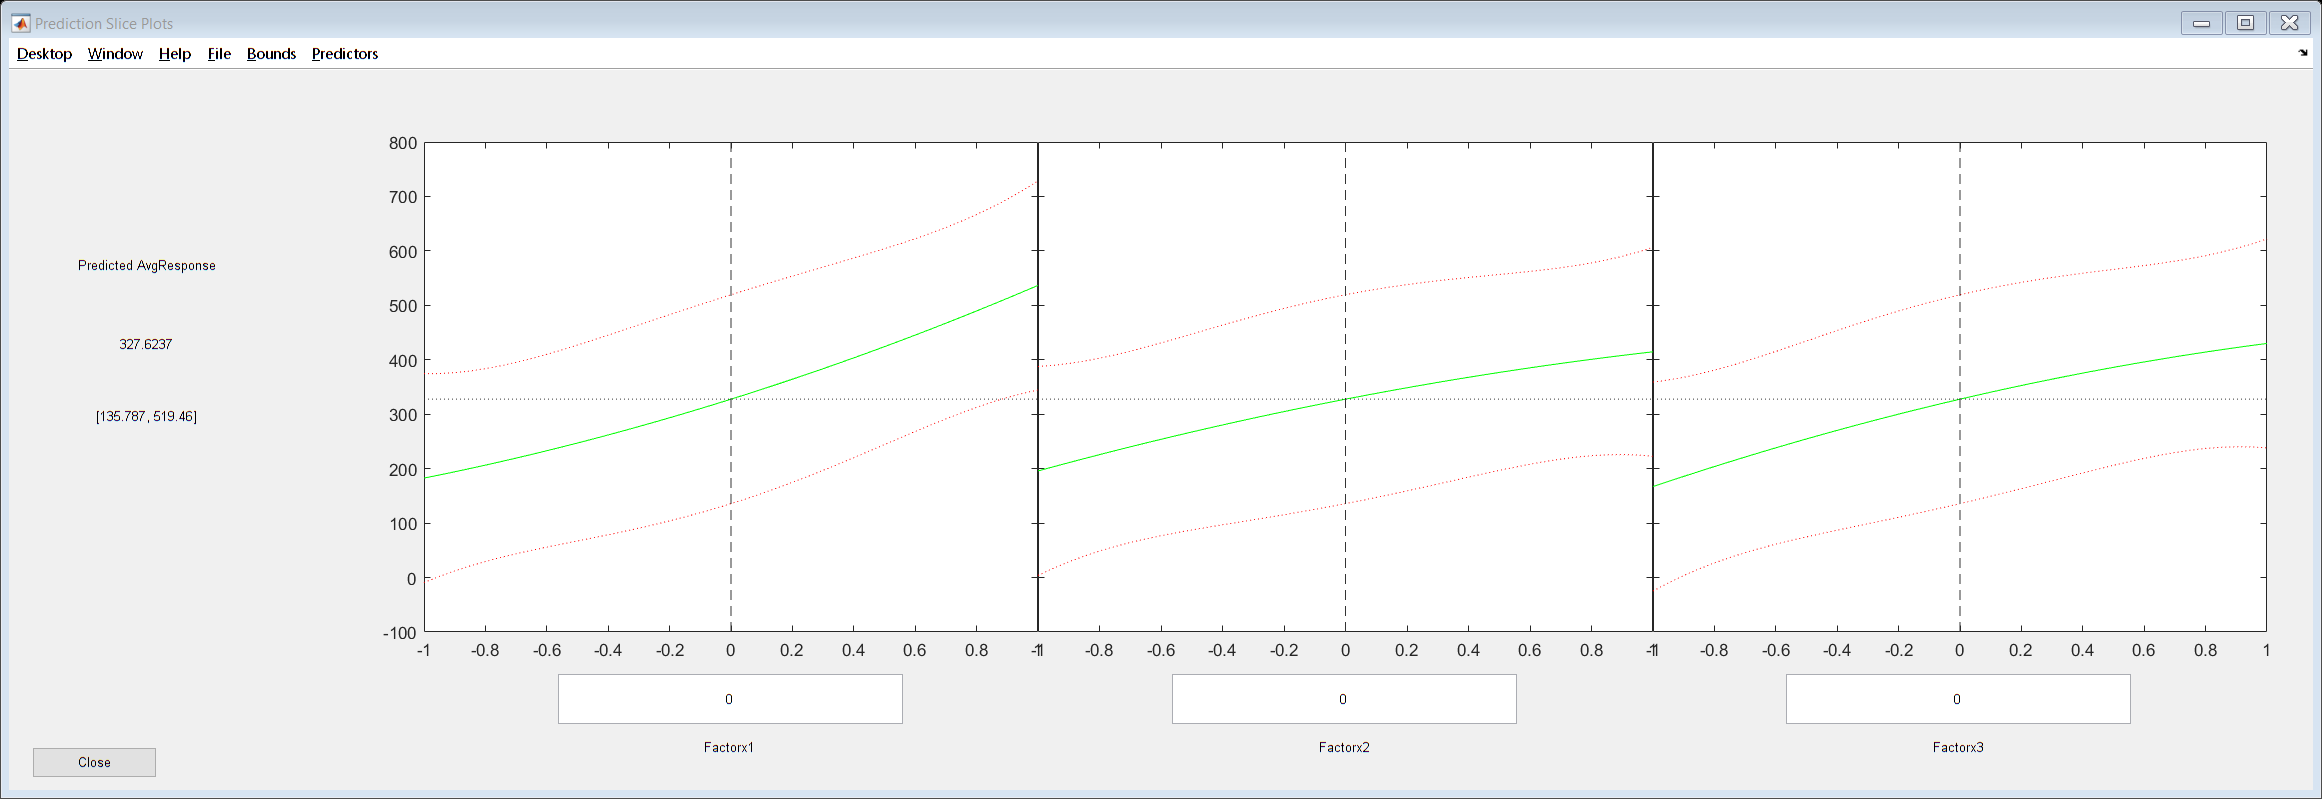

Z23 = nan; % This is the variable to hold the value of the response.
for i = 1:nx2 % First loop; i is the index of the grid's row
    for j = 1:nx3 % Second loop; j is the index of the grid's column

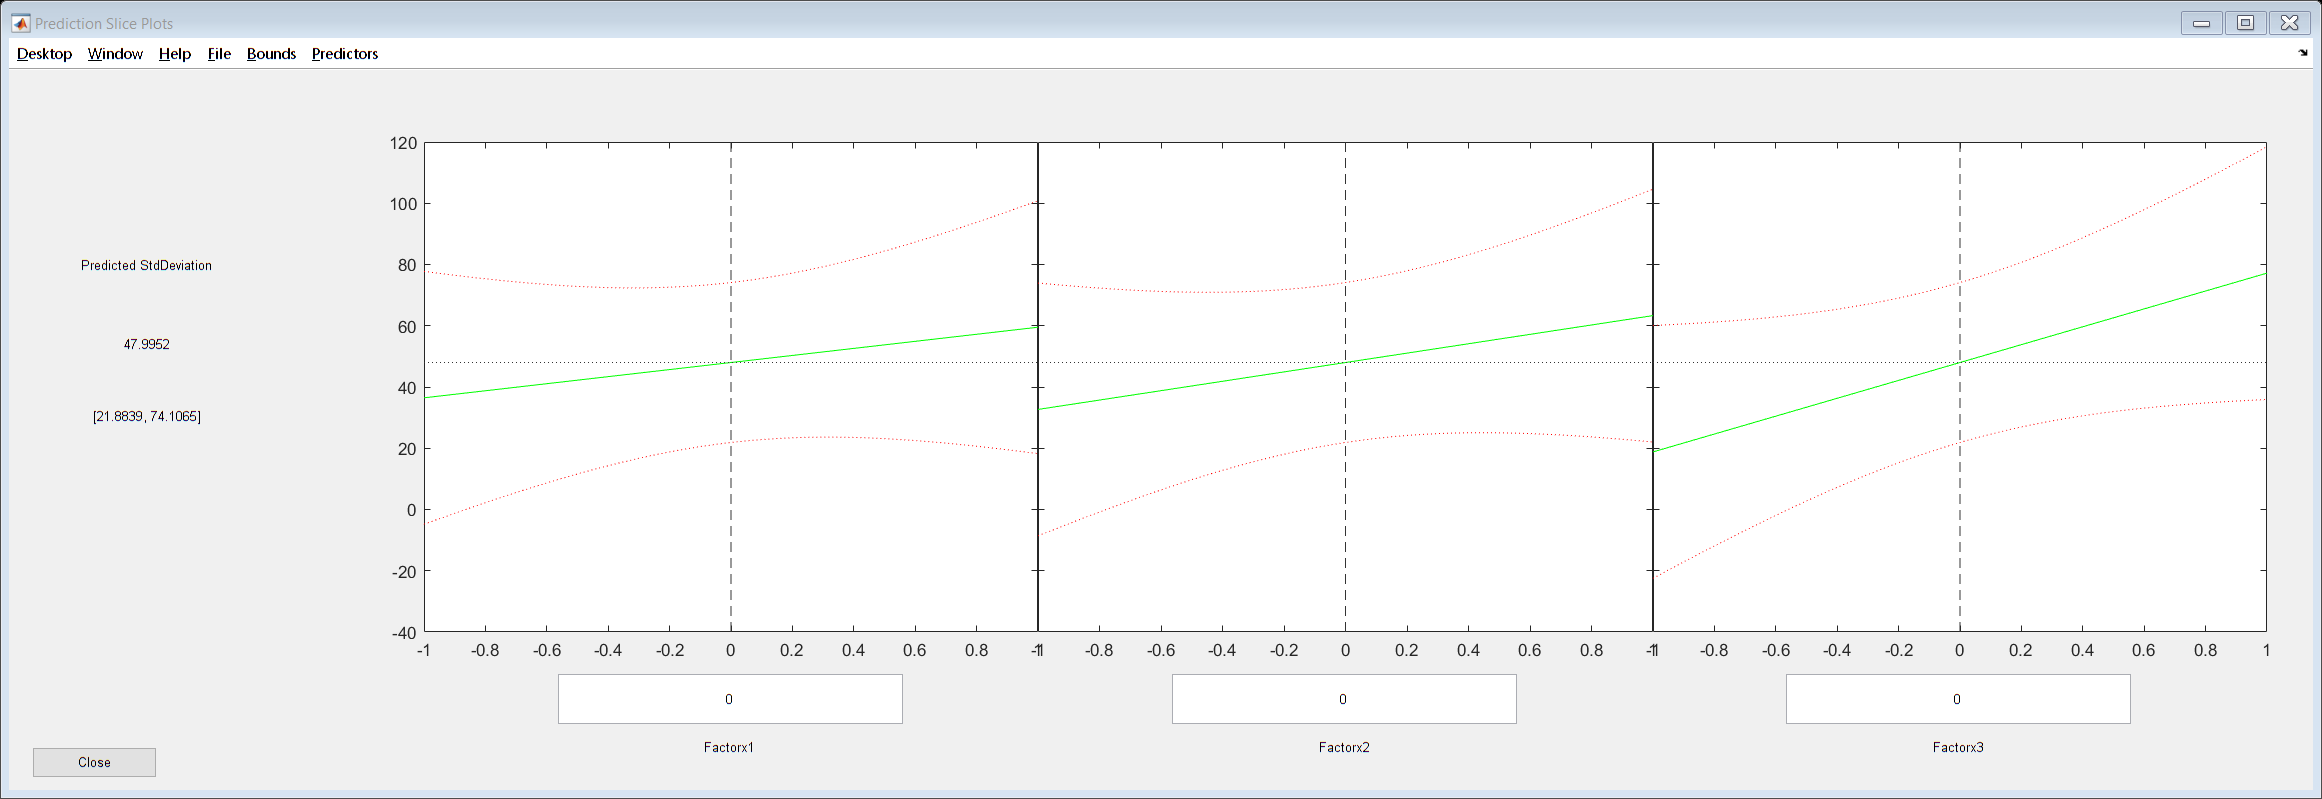

        Z23(i,j) = mu + beta2*X2(i,j) + beta3*X3(i,j) + beta23*X2(i,j)*X3(i,j);

    end
end

% Surface plot
figure;
surfc(X2,X3,Z23); % surfc creates a surface and contour plot

tbl8173 = 10×5 table
                           SumSq       DF      MeanSq         F         pValue  
                         __________    __    __________    _______    __________

    Factorx1             5.6393e+05     1    5.6393e+05      97.33    1.8872e-08
    Factorx2             2.1553e+05     1    2.1553e+05     37.199    1.1803e-05
    Factorx3              3.111e+05     1     3.111e+05     53.693    1.1808e-06
    Factorx1:Factorx2         52317     1         52317     9.0295     0.0079707
    Factorx1:Factorx3         68350     1         68350     11.797     0.0031616
    Factorx2:Factorx3         22794     1         22794     3.9341      0.063709
    Factorx1^2               6146.1     1

c1 = colorbar;
c1.Label.String = 'Response';
title('Response Surface for Model');

mdl8173 = Linear regression model:
    AvgResponse ~ 1 + Factorx1*Factorx2 + Factorx1*Factorx3 + Factorx2*Factorx3

Estimated Coefficients:
                         Estimate      SE      tStat       pValue  
                         ________    ______    ______    __________

    (Intercept)           314.67     14.448     21.78    2.1087e-15
    Factorx1                 177     17.695    10.003    3.1474e-09
    Factorx2              109.43     17.695    6.1841     4.846e-06
    Factorx3              131.47     17.695    7.4297    3.5839e-07
    Factorx1:Factorx2     66.028     21.671    3.0468     0.0063673
    Factorx1:Factorx3     75.471     21.671    3.4825     0.0023483
    Factorx2:Factorx3     43.583     21.671    2.0111      0

xlabel('x2');
ylabel('x3');
zlabel('Average Response');

tbl8184 = 4×5 table
                SumSq     DF    MeanSq      F        pValue  
                ______    __    ______    ______    _________

    Factorx1      2392     1      2392     1.453       0.2403
    Factorx2    4226.5     1    4226.5    2.5673      0.12274
    Factorx3     15339     1     15339    9.3174    0.0056483
    Error        37864    23    1646.2                       



% Contour plot
cl = 40; % Number of contour levels (for increased resolution)
figure;
contour(X2,X3,Z23,cl) % 2D contour plot
title('Contour Plot for Model');
xlabel('x2');
ylabel('x3');
zlabel('Average Response');
c2 = colorbar;
c2.Label.String = 'Average Response';

Terms 1 and 3 only.

[X1,X3] = meshgrid(x1,x3); % meshgrid function returns 2D grid coordinates
% Effects from Factor 2 and 3 only
Z13 = nan; % This is the variable to hold the value of the response.
for i = 1:nx1 % First loop; i is the index of the grid's row
    for j = 1:nx3 % Second loop; j is the index of the grid's column
        Z13(i,j) = mu + beta1*X1(i,j) + beta3*X3(i,j) + beta13*X1(i,j)*X3(i,j);
    end
end

% Surface plot
figure;
surfc(X1,X3,Z13); % surfc creates a surface and contour plot
c1 = colorbar;
c1.Label.String = 'Response';
title('Response Surface for Model');
xlabel('x1');
ylabel('x3');
zlabel('Average Response');

% Contour plot
cl = 40; % Number of contour levels (for increased resolution)
figure;
contour(X1,X3,Z13,cl,'ShowText','on') % 2D contour plot
title('Contour Plot for Model');
xlabel('x1');
ylabel('x3');
c2 = colorbar;
c2.Label.String = 'Average Response';

Standard Deviation

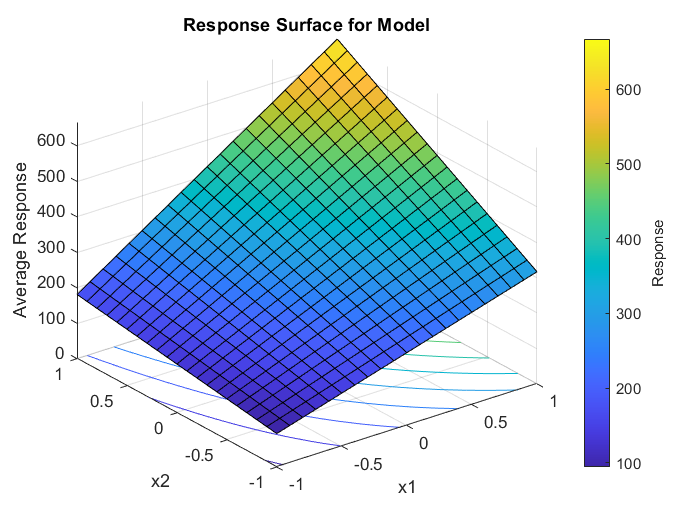

% Create grid
% Nodes
res = 0.1; % Resolution
x1 = [min(fx1):res:max(fx2)]; % Column vector from low level to high level in increments of resolution.
x2 = [min(fx2):res:max(fx2)];
x3 = [min(fx3):res:max(fx3)];

nx1 = length(x1); % Returns the number of elements in the vector - this becomes
% the nodes on our mesh
nx2 = length(x2);

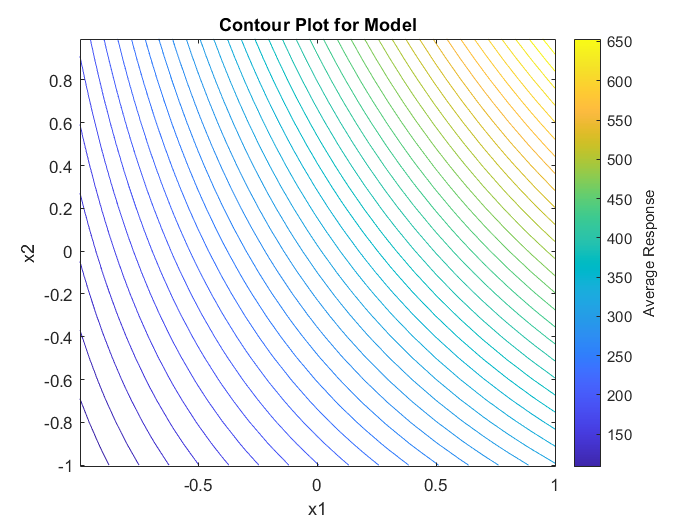

nx3 = length(x3);

[X1,X2] = meshgrid(x1,x2); % meshgrid function returns 2D grid coordinates

% Extract model parameter estimates, known as the regression coefficients
% beta's
betas8172 = mdl8172.Coefficients.Estimate;
mu = betas8172(1,1); % Mean
beta1s = betas8172(2,1); % Regression coefficient for sweetner factor, beta
beta2s = betas8172(3,1);
beta3s = betas8172(4,1);

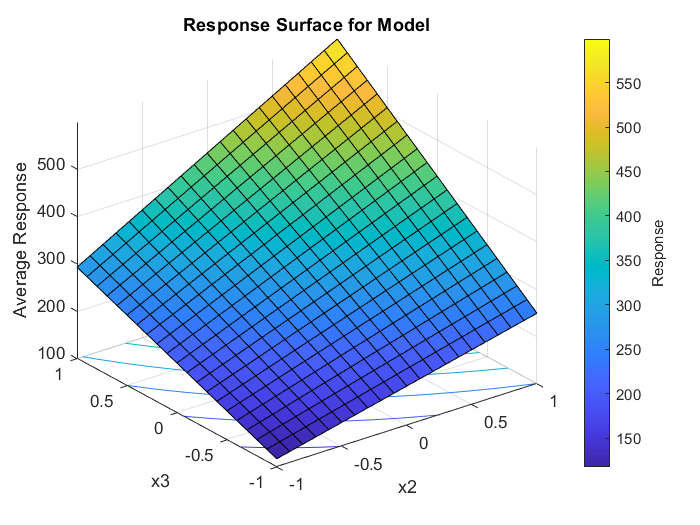


% Evaluate the regression equation at every coordinate within the grid.
% Initalize variable to hold the evaluated equation.
% Effects from Factor 1 and 2 only
Z12s = nan; % This is the variable to hold the value of the response.
for i = 1:nx1 % First loop; i is the index of the grid's row
    for j = 1:nx2 % Second loop; j is the index of the grid's column
        Z12s(i,j) = mu + beta1s*X1(i,j) + beta2s*X2(i,j);
    end
end

% Effects from Factor 1 and 3 only
Z13s = nan; % This is the variable to hold the value of the response.
for i = 1:nx1 % First loop; i is the index of the grid's row
    for j = 1:nx3 % Second loop; j is the index of the grid's column
        Z13s(i,j) = mu + beta1s*X1(i,j) + beta3s*X3(i,j);
    end
end

% Surface plot

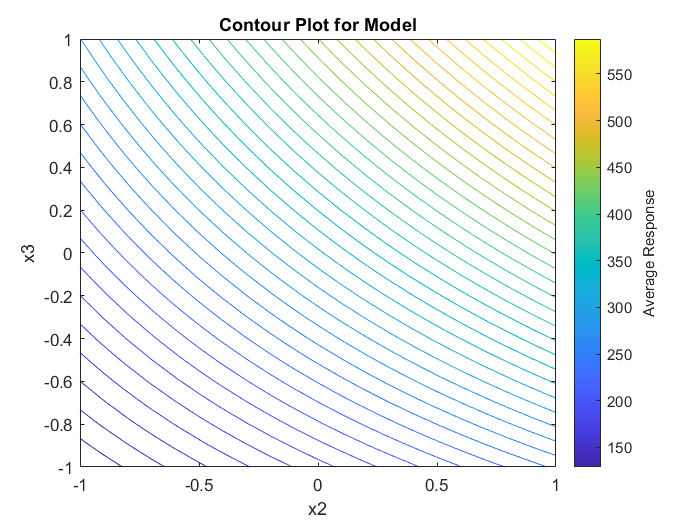

figure;
surfc(X1,X2,Z12s); % surfc creates a surface and contour plot
c1 = colorbar;
c1.Label.String = 'Std Deviation';
title('Response Surface for Model');
xlabel('x1');
ylabel('x2');
zlabel('Std Deviation');

% Contour plot
cl = 40; % Number of contour levels (for increased resolution)

figure;
contour(X1,X2,Z12s,cl) % 2D contour plot
title('Contour Plot for Model');
xlabel('x1');
ylabel('x2');
zlabel('S');
c2 = colorbar;
c2.Label.String = 'Std Deviation';
hold off;

Contour Plot Overlay

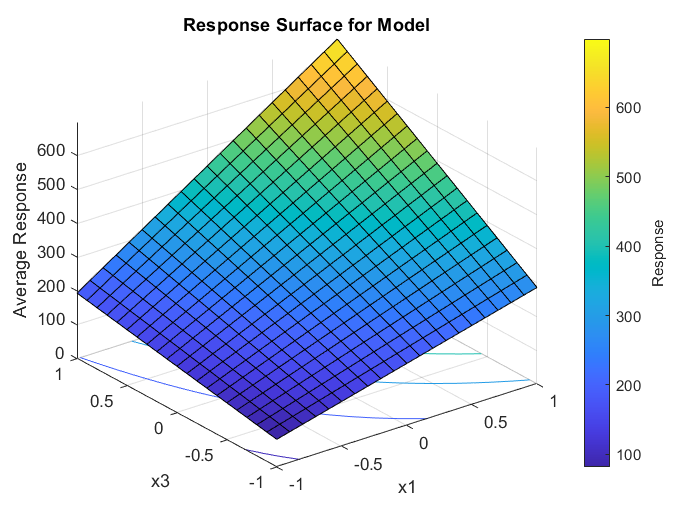

% Factors x1 and x2
hold on;
% Contour plot
cl = 10; % Number of contour levels (for increased resolution)
contourf(X1,X2,Z12,cl,'showtext','on') % 2D contour plot
% Show text display contour labels

% Contour plot
cl = 10; % Number of contour levels (for increased resolution)

contour(X1,X2,Z12s,cl,'--r','showtext','on') % 2D contour plot
title('Contour Plot Overlay for Model');
xlabel('x1');
ylabel('x2');
axis equal; % Use the same length for the data units along each axis.
legend('Average','Std Deviation','location','best');
hold off;

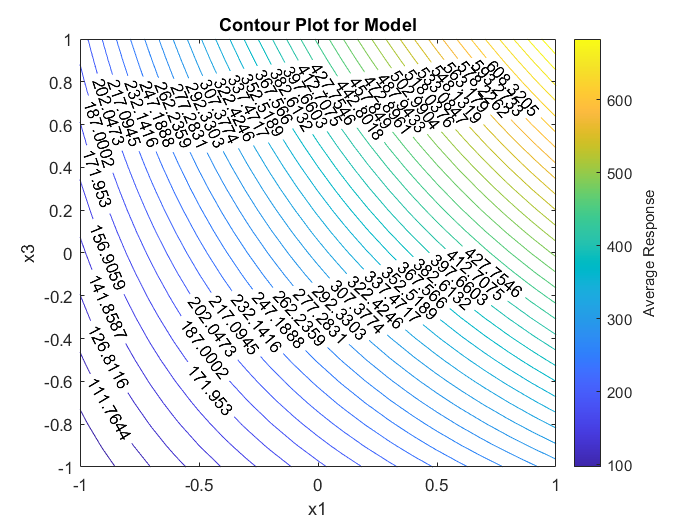

% Factors x1 and x3
hold on;
% Contour plot

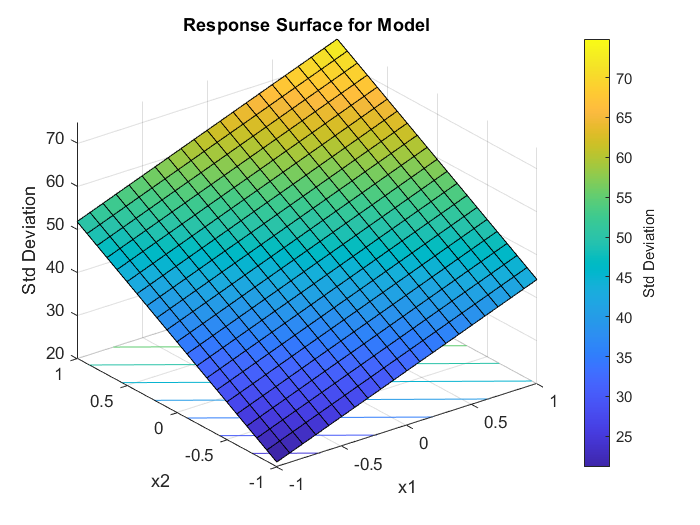

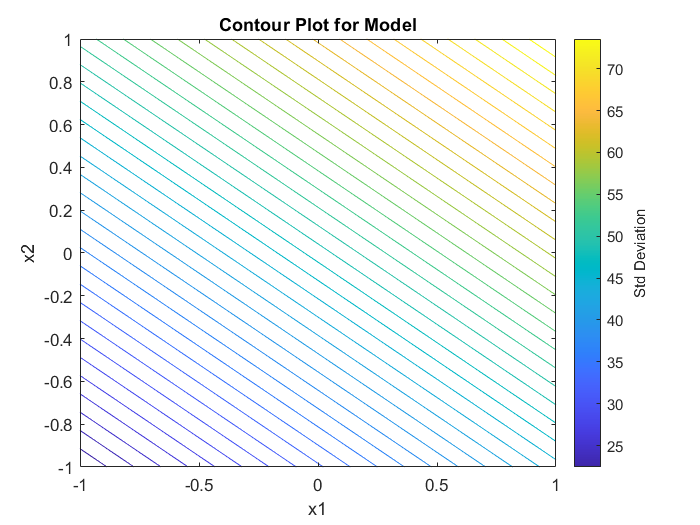

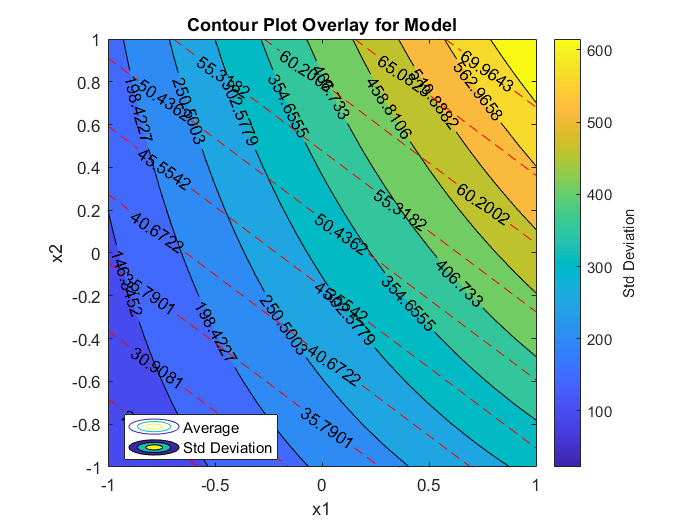

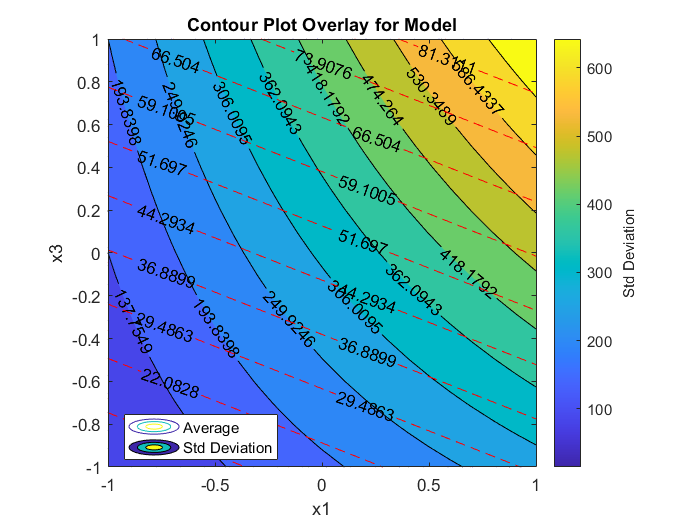

cl = 10; % Number of contour levels (for increased resolution)
contourf(X1,X3,Z13,cl,'showtext','on') % 2D contour plot
% Show text display contour labels

% Contour plot
cl = 10; % Number of contour levels (for increased resolution)
contour(X1,X3,Z13s,cl,'--r','showtext','on') % 2D contour plot
title('Contour Plot Overlay for Model');
xlabel('x1');
ylabel('x3');
axis equal; % Use the same length for the data units along each axis.
legend('Average','Std Deviation','location','best');
hold off;

Problem 8.17 - 3^3 Full-factorial design, cont.

In conclusion, to hit an Average target of 500 while maintaining std deviation low, the factor-level settings should be set to:

x1 = ~ 1.0

x2 = ~ 0.3

x3 = ~ 0.2

Problem 8.17. To hit an Average target of 500 while maintaining std deviation low, the factor-level settings should be set to:

x1 = ~ 1.0

x2 = ~ 0.3

x3 = ~ 0.2

-2.